# **DSP Lab work**

Manasi Kattel

MAIA

# **Signaux**

## **1. DETERMINISTIC SIGNALS**

#### **Question 1**: **Considering the Dirac function corresponding to Equation (1), write a matlab function Dirac to define a discrete signal of length N and containing the Dirac function at the position n (δ(k − n)). Verify inside the function that n ∈ [1, N] and display a warning if it is not the case.**

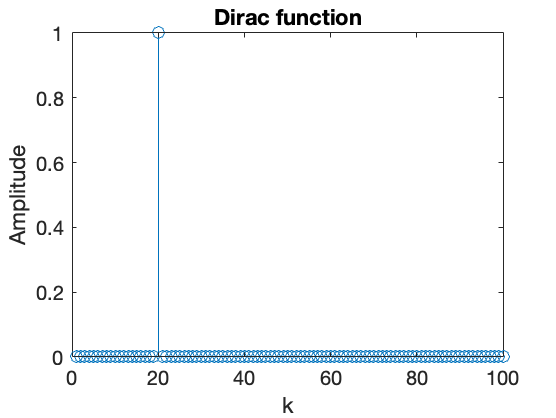

[x,y]  = DiracN(20, 100);
figure;
stem(x,y);
xlabel('k');
ylabel('Amplitude');
title('Dirac function');

#### **Question 2**: Considering the step function H corresponding to Equation (2), write a matlab function step to define a discrete signal of length N and containing the value of the step function shifted at the position n (H(k − n)). Verify inside the function that n ∈ [1, N] and display a warning if it is not the case.

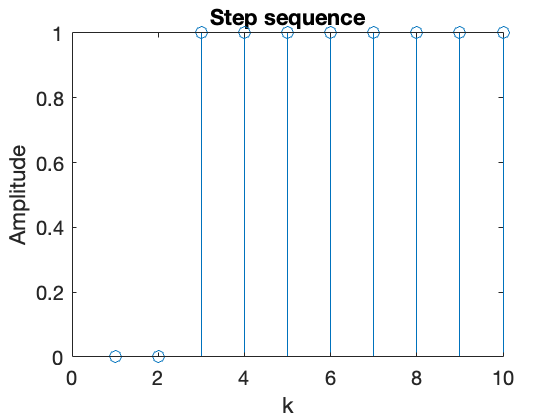

[x,y] = Step(10,3);
figure;
stem(x,y);
xlabel('k');
ylabel('Amplitude');
title('Step sequence');

#### **Question 3**:Considering the ramp function P(k) corresponding to Equation (??), write a matlab function ramp to define a discrete signal of length N and containing the values of the ramp function shifted at the position n with a slope a : a:P (k - n). Verify inside the function that n 2 [1;N] and display a warning if it is not the case.

#### P(k) = k if k  >= 0

####             0 elsewhere

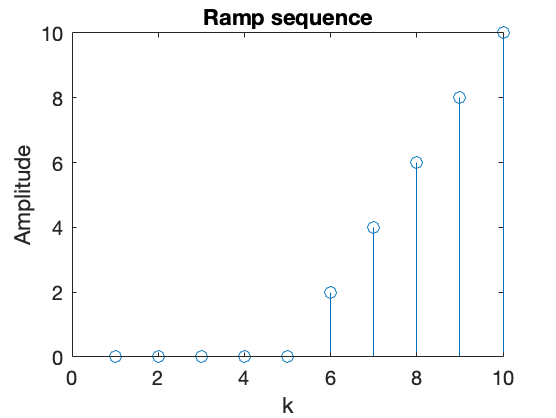

[x,y] = Ramp(10,5,2);
figure;
stem(x,y);
xlabel('k');
ylabel('Amplitude');
title('Ramp sequence');

#### **Question 4**: Considering the geometric function G(k) corresponding to Equation (??), write a matlab function geo to de ne a discrete signal of length N and containing the values of the geometric function shifted at the position n (G(k-n)). Verify inside the function that n 2 [1;N] and display a warning if it is not the case.

#### G(k) = a^k if k  >=0

#### 0 elsewhere

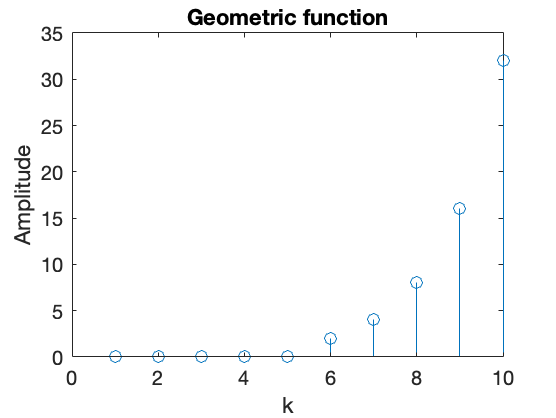

[x,y] = GeomFunc(2,5,10);
figure;
stem(x,y);  
xlabel('k');
ylabel('Amplitude');
title('Geometric function');

#### **Question 5**:Considering the box function B(k) corresponding to Equation (??), write a matlab function box to define a discrete signal of length N and containing the values of the box function shifted at the position n with a half-width a : Ba(k - n). Verify inside the function that n belongs to [1 + a;N - a] and display a warning if it is not the case.

#### Ba(k) = 1 if a  <=k <=  a

####              0 elsewhere

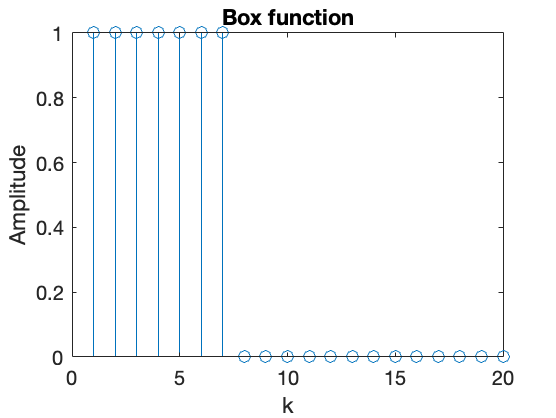

[x,y] = boxf(20,4,3);
figure;
stem(x,y);
xlabel('k');
ylabel('Amplitude');
title('Box function');

#### **Question 6**: Write a matlab function sinus to define a discrete signal of length N and containing the values of sin(2 fnTs) where the parameters are the frequency, the number of periods (can be non-integer), the length or the sampling frequency. Take care of the discrete definition of this function: the repetition of the signal defined for an integer number of periods should not produce artefacts.

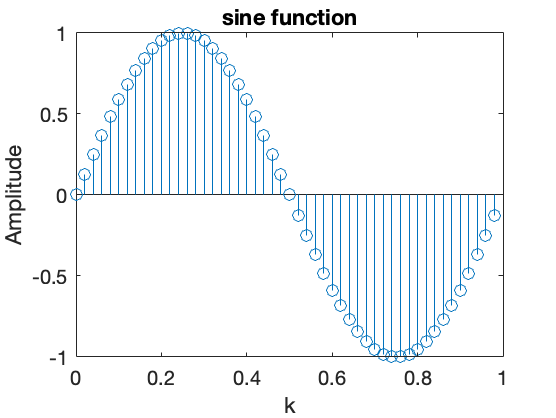

[x,y] = sinusf(1,50,1);
figure;
stem(x,y);
xlabel('k');
ylabel('Amplitude');
title('sine function')

## **2. RANDOM SIGNALS**

#### **Question 1: Generate (matlab function randn) an observation xn (length 1000 points or more) of the normal/gaussian random process N. Plot the distribution of the values of this observation.**

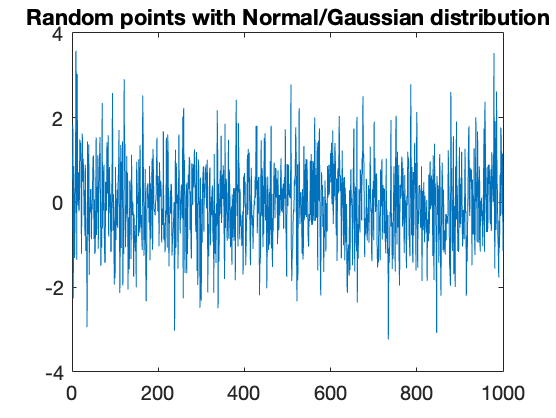

n= 1000;
x_n = randn([1,n]);
figure;
plot(x_n);
title("Random points with Normal/Gaussian distribution");

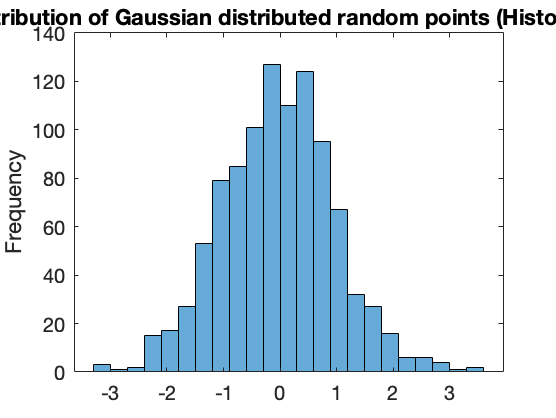



figure;
histogram(x_n);
ylabel('Frequency')
title("Distribution of Gaussian distributed random points (Histogram)");

#### Question 2: Same question with the uniform law of the random process U and an observation xu.

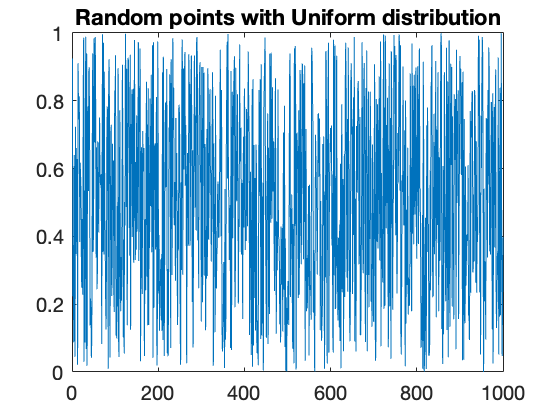

x_r = rand([1,n]);
figure;
plot(x_r);
title("Random points with Uniform distribution");

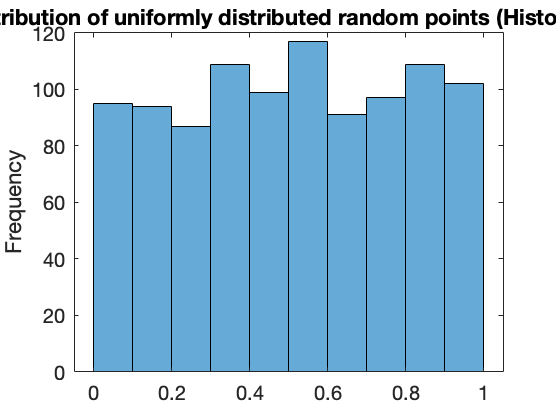


figure;
histogram(x_r);
ylabel('Frequency');
title("Distribution of uniformly distributed random points (Histogram)");

#### Question 3: Compute the autocorrelation of the two observations. Are these noises "white" ? Conclusion?

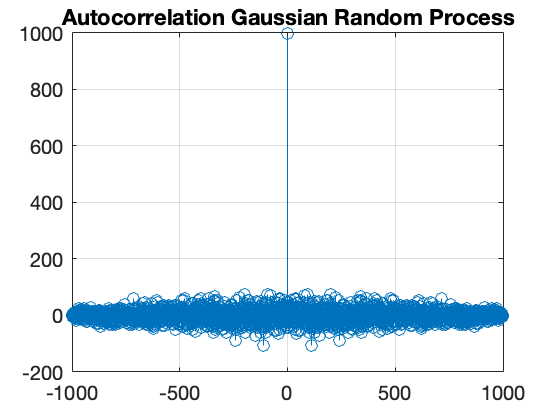

[c,lags] = xcorr(x_n,x_n);
figure;
stem(lags,c); 
title("Autocorrelation Gauss/Normal random process");title("Autocorrelation Gaussian Random Process"); grid on;

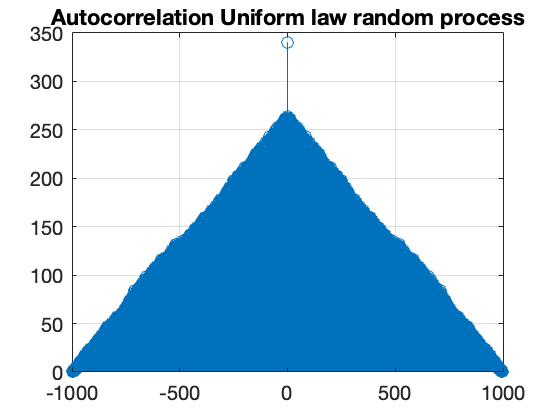

[c,lags] = xcorr(x_r,x_r);
figure;
stem(lags,c); 
title("Autocorrelation Uniform law random process");grid on;

#### Are these noises "White"? Conclusion?

White noise is a random signal having equal intensity at different frequencies, giving it a constant power spectral density. Its auto correlation function is **an impulse at lag 0**

**Yes**, both noises are "white" because white noise has an impulse at lag 0.

#### Question 4: Generate three binary random signals s1; s2; s3 thanks to the instruction round(rand(1; 50)). Generate a whole signal s containing these signals at different shifts. Compute the cross-correlation between the whole signals and s1; s2; s3.

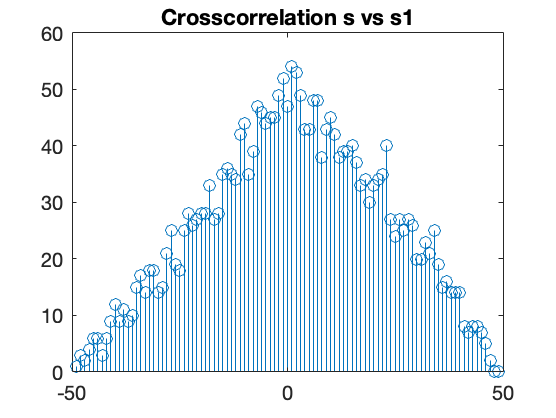

% Discrete random variables 
s1 = round(rand(1,50));
s2 = round(rand(1,50));
s3 = round(rand(1,50));
% Use circshift function in order to shift the vector
% in a random number [1-50].
s11 = circshift(s1,round(rand*50));
s22 = circshift(s2,round(rand*50));
s33 = circshift(s3,round(rand*50));
% Then, combine the three random vectors in one.
s=s11+s22+s33;
% Get the information from the correlation between the
% combine vector with each other single vectors
[c1,lags1] = xcorr(s,s1);
[c2,lags2] = xcorr(s,s2);
[c3,lags3] = xcorr(s,s3);
% Display   
figure;
stem(lags1,c1); title('Crosscorrelation s vs s1');

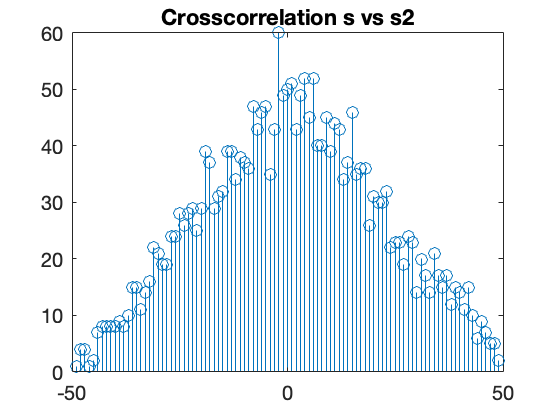

figure;
stem(lags2,c2); title('Crosscorrelation s vs s2');

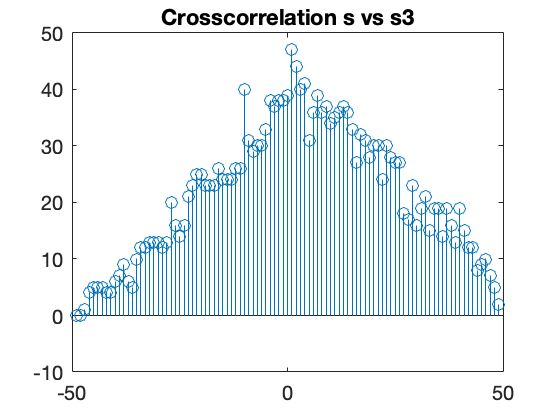

figure;
stem(lags3,c3); title('Crosscorrelation s vs s3');

# **Systems**

## **3. CAUSALITY**

### **Question 1:**

Considering the system defined by the equation yk = (xk + xk+1)/2, check its causality property by examining the response to the signal H(k − 4) or step(4,N). When plotting, include the abscissa range [1 : N].

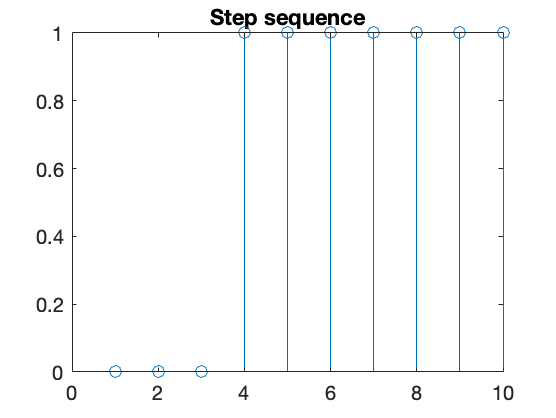

%Plots the step function, to compare
[x,y] = Step(10,4);
figure;
stem(x,y);
title('Step sequence');

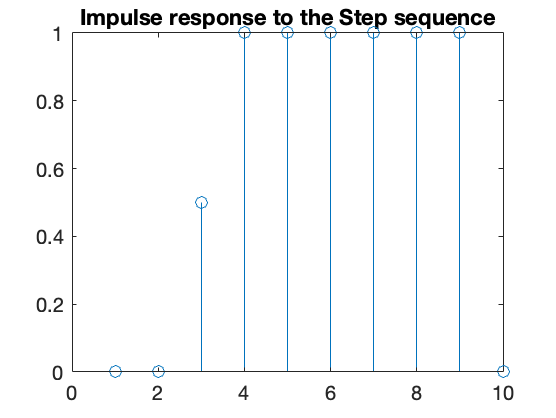


%Plots the impulse response of the system
[x,y] = system1(x,y);
figure;
stem(x,y);
title('Impulse response to the Step sequence');

The system here is not causal as it depends on future value (xk+1).

### Question 2: Propose a modification to obtain a causal version.

Given that a causal system is independent from future values, a modification could be done to the x(k+1) part of the equation. We remove the term x_(k+1) and shift another unit step signal with shift+1 and modify the equation to be (x_(k)+x_(k-1))/2.

## **4. STABILITY**

### **Question 1:**

Program the primitive (accumulator) operator prim(f) applied on the signal f of length N. The value of the vector returned by prim at the index k will correspond to Fk with k ≤ N. Note Fk = Pk q=−∞ fk. Discuss on the result of the primitive operator applied to the signal H(k − 4). Is the primitive operator stable ?

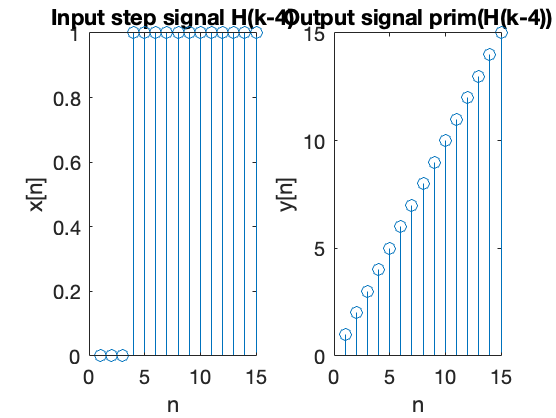

N = 15;
% x = 1:N;
[x,y] = Step(N,4);
figure;
subplot(1,2,1);
stem(x,y);
title('Input step signal H(k-4)'), xlabel('n'), ylabel('x[n]')
subplot(1,2,2);
stem(prim(x,y));
title('Output signal prim(H(k-4))'), xlabel('n'), ylabel('y[n]')

The primitive operator is unstable, a bounded input (as the step) results in an unbounded output.

#### **Question 2: What is the impulse response of the primitive operator (in the discrete domain) ?**

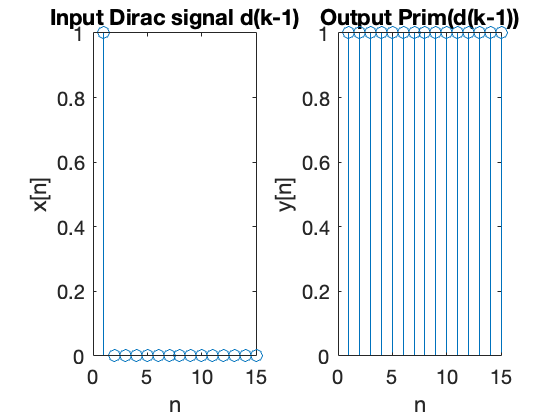

[x,y] = DiracN(1,15);

subplot(1,2,1), stem(x,y);
title('Input Dirac signal d(k-1)'), xlabel('n'), ylabel('x[n]');
subplot(1,2,2);

[x_, y_] = prim(x,y);
stem(x_,y_);
title('Output Prim(d(k-1))'), xlabel('n'), ylabel('y[n]')

The impulse reponse of prim operator is ramp. The prim operator is  unstable as a step input (bounded input) results in an unbounded output(ramp approaching inf).

#### **Question 3: Test the stability of the system defined by the equation: yk = xk +2yk-1. Plot the impulse response.**

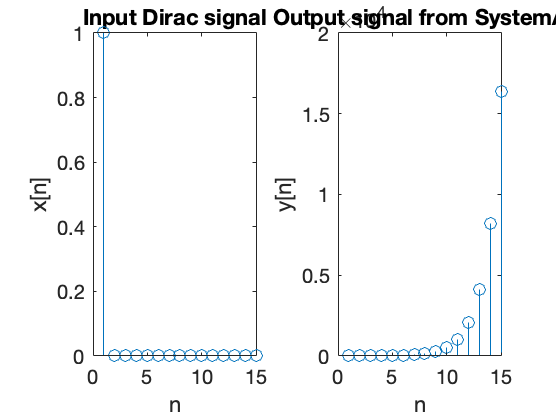

[x,y] = DiracN(1,15);
subplot(1,2,1), stem(x,y);
title('Input Dirac signal'), xlabel('n'), ylabel('x[n]')
subplot(1,2,2), 
[x_, y_] = systemA(x,y);
stem(x_,y_);
title('Output signal from SystemA'), xlabel('n'), ylabel('y[n]')

The system is **unstable**, given a bounded input (dirac, having a value 1 at zero and zeros elsewhere) the output grows exponentially, diverging and leading to an unbounded output. 

#### **Question 4: Test the stability of the system de ned by the equation: yk = xk + yk-1=3. Plot the impulse response. Write the response y as a convolution operation (truncate the impulse response).**

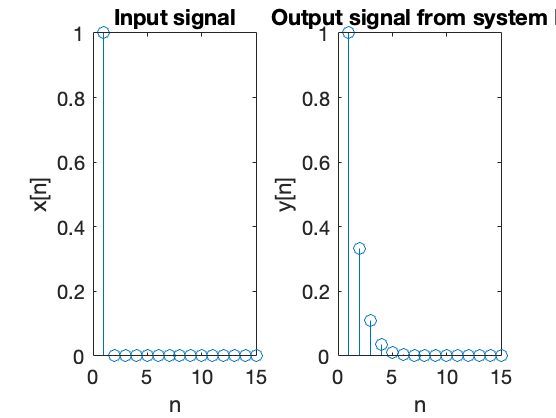


figure, subplot(1,2,1), stem(x,y)
title('Input signal'), xlabel('n'), ylabel('x[n]')
subplot(1,2,2);

[x_,y_] = systemB(x,y);
stem(x_,y_);
title('Output signal from system B'), xlabel('n'), ylabel('y[n]')

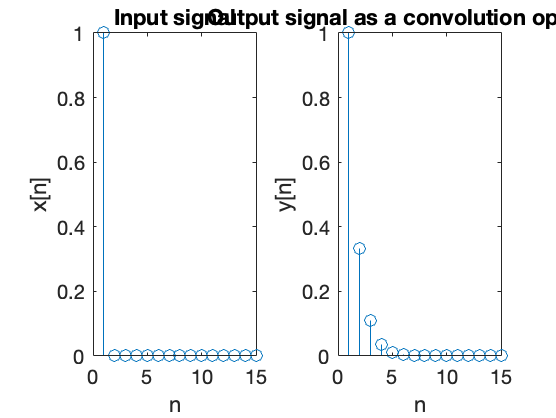


% Writing the response as a convolution operation 
x = shifted_dirac(1,15);
h = ((1/3).^(0:14)).*shifted_step(1,15);
y = conv(h, x, "full");
figure,subplot(1,2,1), stem(x)
title('Input signal'), xlabel('n'), ylabel('x[n]')
subplot(1,2,2), stem(y(1:15))
title('Output signal as a convolution operation'), xlabel('n'), ylabel('y[n]')

**Stable system**: applying the system to a bounded input (only values smaller or equal to one) leads us to a bounded output, with no value greater than one.

## **5. INVARIANCE AND LINEARITY**

#### **Question 1: De ne the following signals: xa = [0 0 0 0 1 2 3 4 5 0 0 0 0 0 0 0 0 0 0]; xb = [0 0 0 0 0 0 0 0 0 4 3 2 1 0 0 0 0 0 0];. Compute the responses ya, yb according to the equation y = 3xk-1 - 2xk + xk+1**

xa = [0,0,0,0,1,2,3,4,5,0,0,0,0,0,0,0,0,0,0];
xb = [0,0,0,0,0,0,0,0,0,4,3,2,1,0,0,0,0,0,0];
ya = y_response(xa);
yb = y_response(xb);

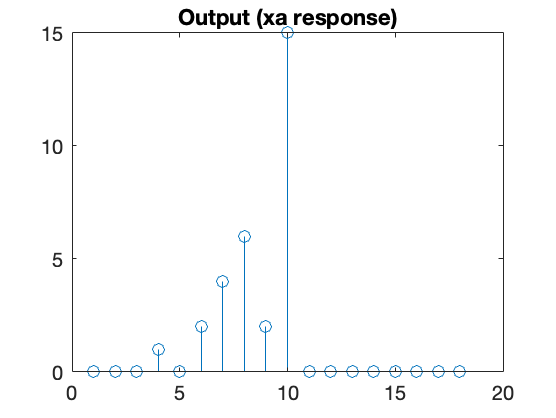

figure;
stem(ya);
title('Output (xa response)');

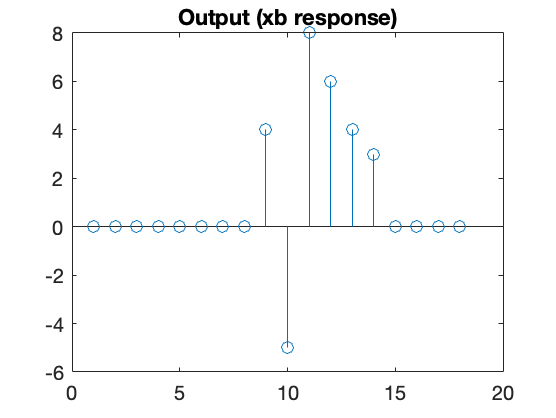

figure;
stem(yb);
title('Output (xb response)');

yr = ya+yb; 
yab = y_response(xa+xb);

%Shifting the signal to prove the invariance
xa_shift = shft(xa,2);
xb_shift = shft(xb,2);
output = shft(yab,2);
output2 = y_response(xa_shift);
output3 = y_response(xb_shift);
ya_shift = shft(ya, 2);
yb_shift = shft(yb, 2);

if isequal(yr,yab)
  disp ('The system is linear')
else
  disp("The system is non-linear");

end

The system is linear



if isequal(ya_shift,output2) && isequal(yb_shift,output3)
    disp('The system is time invariant')
else
    disp('The system is time variant')

end

The system is time invariant


#### **Question 3: Propose a nonlinear/noninvariant system.**

An example of a nonlinear and noninvariant system is the following:

y = x[2k − 1] − 6(x[k])^2 + x[k + 1] 

For a system to be linear, it must fulfill the following condition:

y[aX1 + bX2] = ay[X1] + by[X2] (3)

For a system to be invariant, it must fulfill the following condition:

τ{X[t − k]} = y[t − k] 

For a shifted input signal, the system should also produce a shifted output signal.

**Examples of nonlinear and noninvariant systems:**

y[k] = 3x[2k − 1] − 2x[k]^4 + x[k + 1]

**Nonlinear system**

y[k] = 3x[k − 1] − 2x[k]^2 + x[k + 1]

**Noninvariant system**

y[k] = 3x[3k − 1] − 2x[k] + x[k + 1]

y[k] = 3 ∗ k ∗ x[k − 1] − 2x[k] + x[k + 1] 

## **6. CONVOLUTION**

#### **Question 1**: Try to write a simple version of the convolution function (do no process the limits of the signal). 

% This is to make the test (you can introduce the values here)
n = -20:20;
x = sin(n);            
h = [-1,-2,8,-2,-1];  

We make the call to our function:

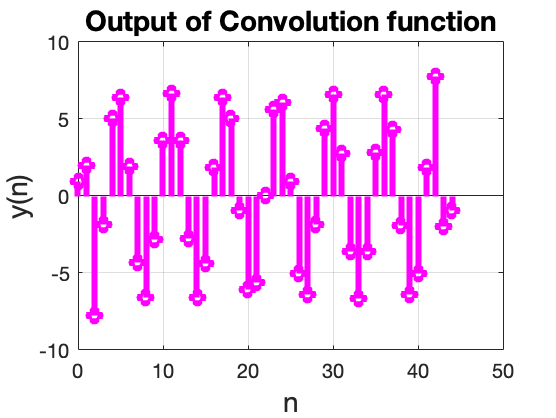

convsignal=convolutionfunction(x, h); % The definition of the function is above all (in the appendix)
Ny = length(convsignal);
m = 0: Ny-1;
% Make plot
figure
stem(m,convsignal,'linewidth',3,'color','m')
grid;
a = title('Output of Convolution function');
set(a,'fontsize',14);
a = ylabel('y(n)');
set(a,'Fontsize',14);
a = xlabel('n');
set(a,'Fontsize',14);

Using matlab built function (conv) we get the same results (this is only to verify our function)

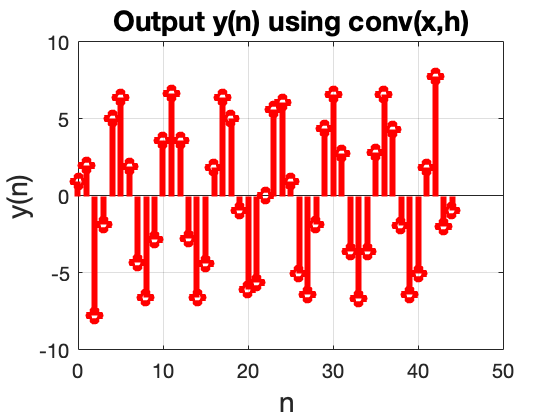

figure;
y2 = conv(x,h);
N = length(x);
M = length(h);
stem(0:(N+M-2),y2,'linewidth',3,'color','r')
grid;
a = title('Output y(n) using conv(x,h)');
set(a,'fontsize',14);
a = ylabel('y(n)');
set(a,'Fontsize',14);
a = xlabel('n ');
set(a,'Fontsize',14);

#### **Question 2**: Generate (matlab function randn) an observation xn (length 1000 points or more) of the normal/gaussian random process N . Plot the distribution of the values of this observation. Compute the convolution product (y) of xn with the values h = [18 8 5 2 1] (conv(x, h, ’same’)). Compute the cross-correlation of xn with y and observe the result.

First we generate the observation xn and plot it. 

% clear variables
% close all
xn=randn(1,1000);
figure;
a = plot(xn,'LineWidth',2);
hold on;

After that, we compute the convolution product with the given filter

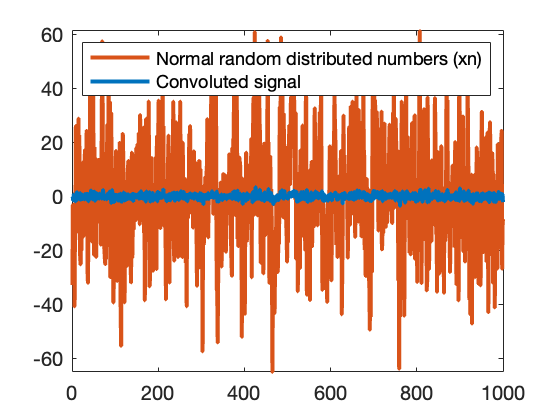

h=[18 8 5 2 1];
y=conv(xn, h,'same');
plot(y,'LineWidth',2);
b = uistack(a,'top');
legend('Normal random distributed numbers (xn)',['Convoluted signal']);

Finally, we compute the cross-correlation and extract a conclusion

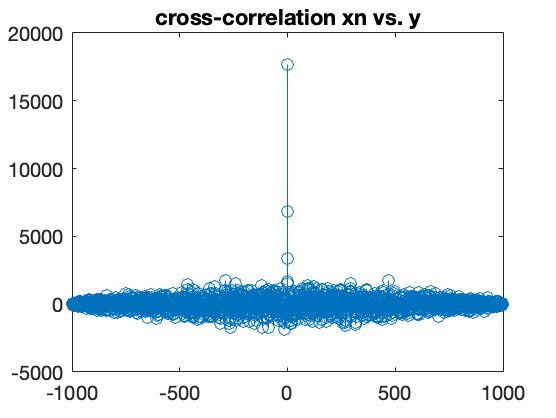

figure;
[c,lags] = xcorr(xn,y);
stem(lags,c);
title('cross-correlation xn vs. y');

**Conlusion**: A very large value appears in the center of the correlation when x matches itself almost exactly (a gaussian random distribution).

# **Convolution**

## 7. 1D CONV

#### Question 1: Defining a signal x and an impulse response h as parameters, write a program convN to compute the convolution product y = h ∗ x. Do not use the matlab function conv and do not take into account the border-problem: the result will be shorter than the input signal.

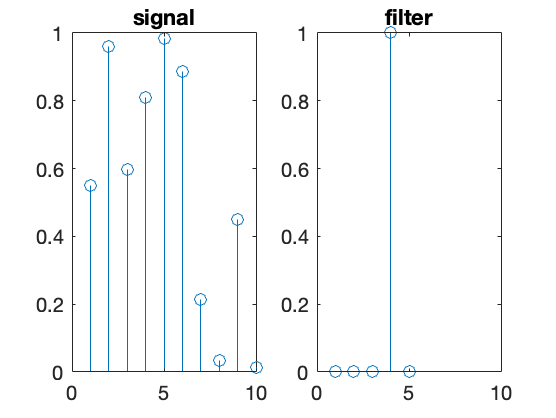

n=10;
x=rand([1,n]);
figure;
subplot(1,2,1);
stem(x);
title("signal")

[th,h] = DiracN(4,5);

subplot(1,2,2);
stem(h);
xlim([0 n]);
title("filter")

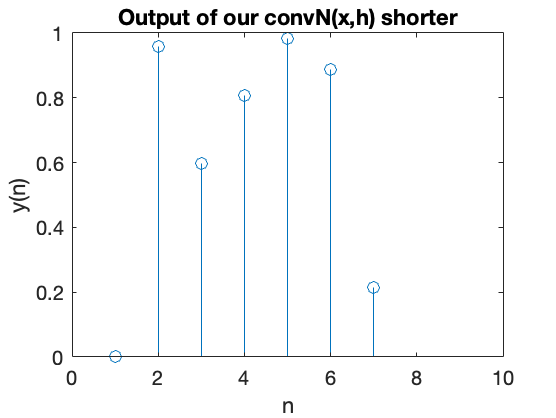


%our Conv
[tNew,yNew]=convN(x,h);

figure
stem(tNew,yNew);
xlim([0 n])
title('Output of our convN(x,h) shorter');
ylabel('y(n)');
xlabel('n');

#### Question 2: Extend (by length(h)-1) the signal x on the left and on the right by 0-padding. Produce a result y having the length of x.

[x2,y2] = convN(x,h,"zero"); %zero-padding
figure,stem(x2,y2),title("Convolution output zero padding"),
xlim([0 n]);

#### Question 3: Introduce the parameter zeroh to localize the 0 of the impulse response. Extract the output accordingly.

[y2,zeroh] = convN(x,h);

#### Question 4: Generalize the border process to extend the signal x by zero-value padding or border-value padding or symmetry or periodicity or border-value symmetry (at left: x−k = 2x0 − xk, note x0 corresponds to x(1) in matlab).

`Change third parameter of function convN to:`

- `"zero" for zero-padding`

- `"border" to pad the signal with the same first/last element`

- `"symmetric" to pad as placing a mirror at each end`

- `"periodic" to pad as if the signal is periodic`

- `"borsym", to pad with border-value symmetry (as in the PDF)`

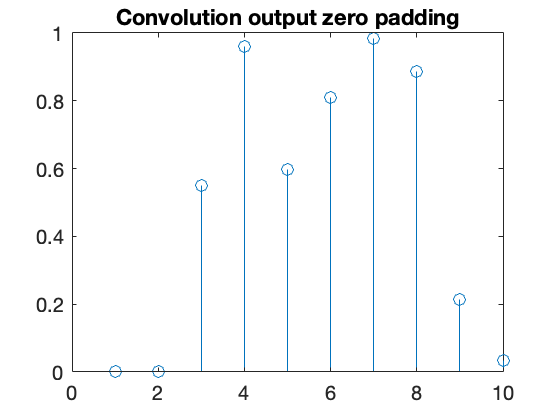

[x3,y3] = convN(x,h,"periodic");
xlim([0 n]);

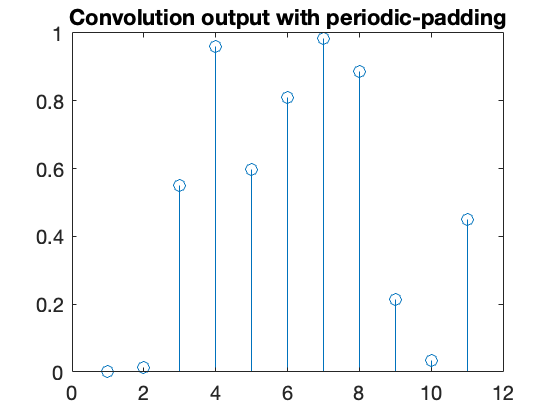

figure,stem(y3),title("Convolution output with periodic-padding")

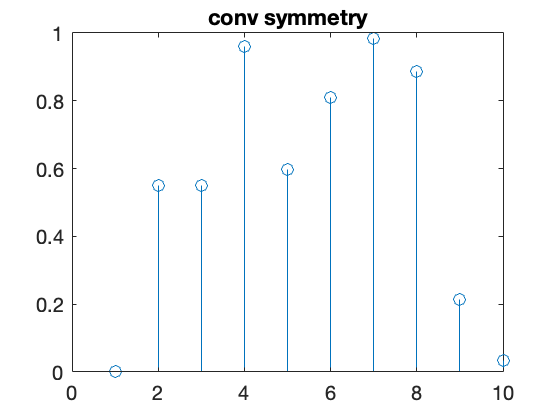

figure;
[tNew,yNew] = convN(x,h,"symmetry");
stem(tNew,yNew);
xlim([0 n])
title('conv symmetry');

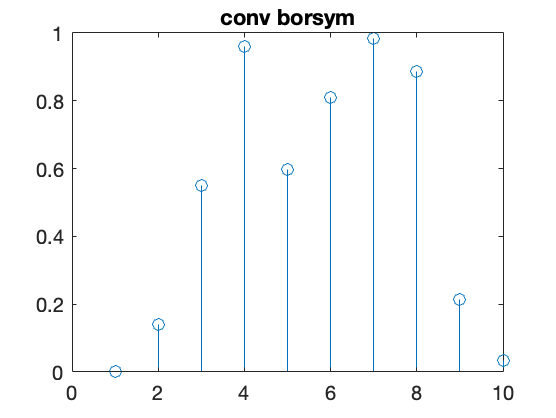

figure;
[tNew,yNew] = convN(x,h,"borsym");
stem(tNew,yNew);
xlim([0 n])
title('conv borsym');

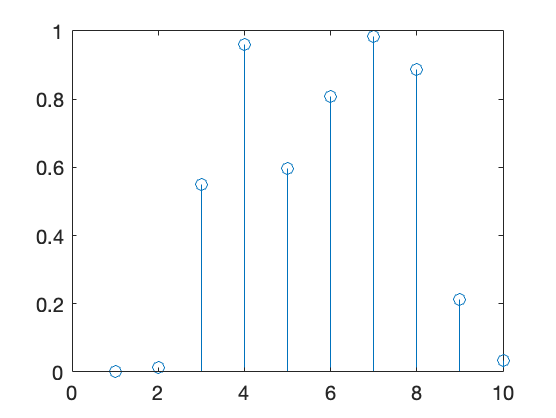

figure;
[tNew,yNew] = convN(x,h,"border");
stem(tNew,yNew);
xlim([0 n]);

## 8. APPLICATIONS: REGULARIZED DERIVATIVES

#### Question 1: Define a signal x and observe the effect of the 0 location in the impulse response h = [1 1 1]/3.

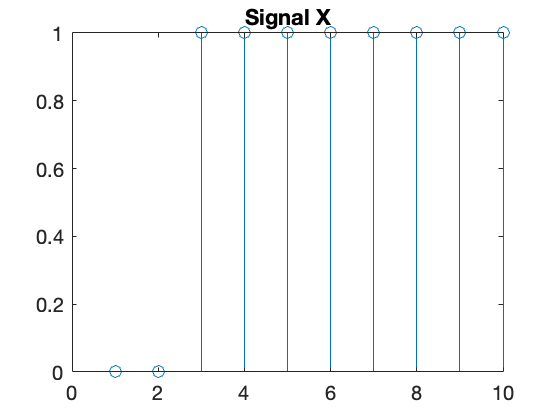

h = 1/3*[1 1 1];
n=10;
[x,y] = Step(n,3);
[x1,z1,~] = convN(y,h,"zero"); 
figure;
stem(x,y);
title("Signal X");

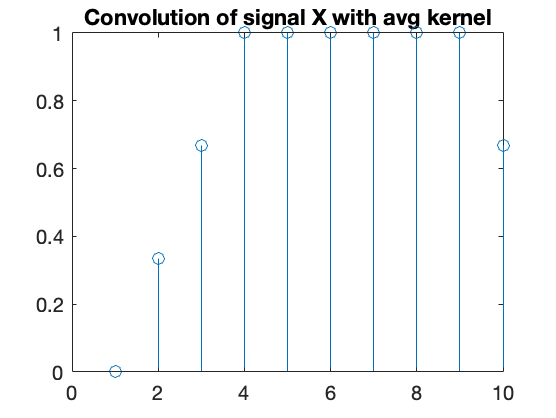

figure;
stem(z1);
title("Convolution of signal X with avg kernel");

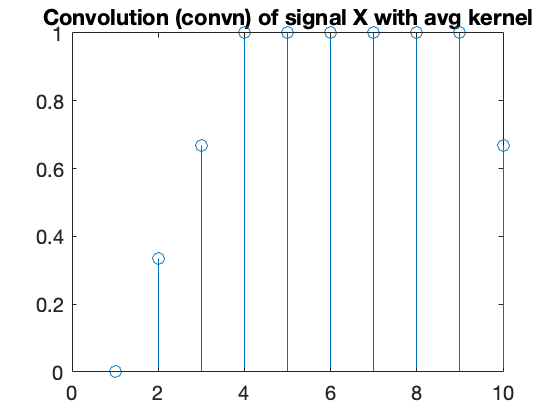

figure;
stem(x1,z1);
title("Convolution (convn) of signal X with avg kernel");

#### Question 2: Apply the elementary derivative [1 −1] or [1 −1]. Apply [1 1] on the previous result.

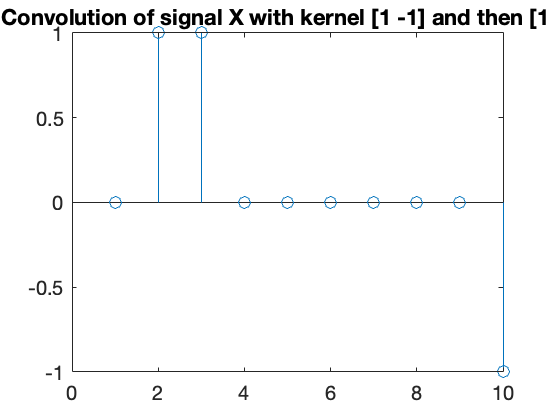

h1 = [1 -1];
h2 = [-1 1];
h3 = [1 1];
d1 = conv(y,h1); 
d1_avg = conv(d1,h3,"valid");
figure
stem(d1_avg)
title("Convolution of signal X with kernel [1 -1] and then [1 1]")

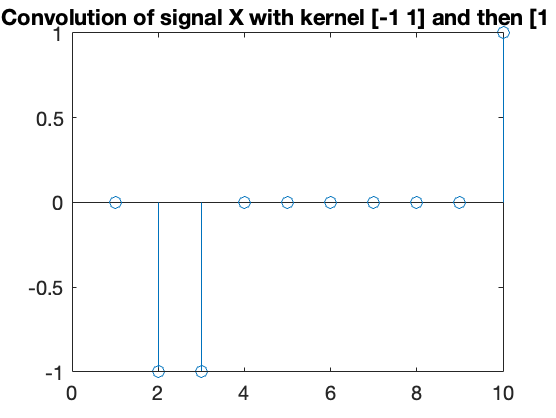

d1 = conv(y,h2);
z=conv(d1,h3,"valid");
figure
stem(z)
title("Convolution of signal X with kernel [-1 1] and then [1 1]")

#### Question 3: Apply h = [1 0 − 1] on x and compare the result to the one of the above question.

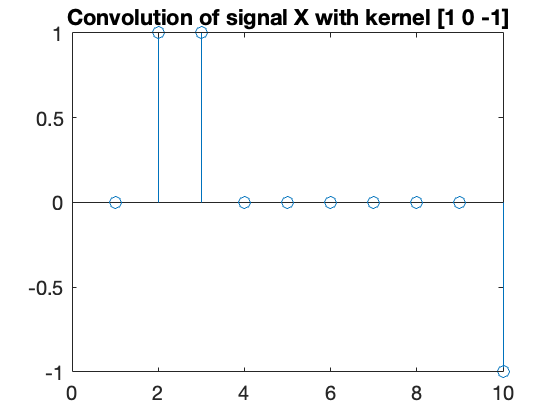

h4 = [1 0 -1]; 
[~,d3] = convN(y,h4,'zero'); 
figure
stem(d3)
title("Convolution of signal X with kernel [1 0 -1]")

The result of applying [1 0 -1] to the signal yields the same output signal as applying two elementary derivatives [1 -1]  and [1 1] consecutively .

#### Question 4: Apply the elementary derivative two times. Find the equivalent impulse response (one convolution).

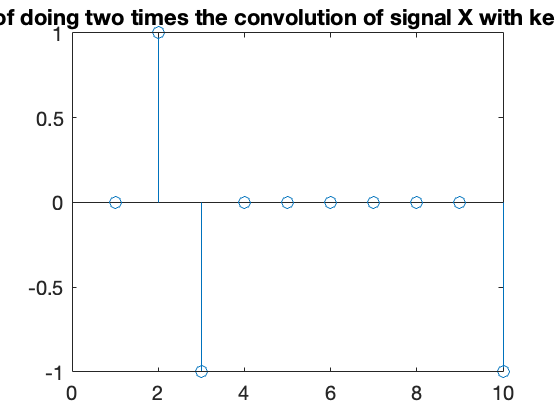

z = conv(y,h1);
z=conv(z,h1,"valid");
figure
stem(z)
title("Result of doing two times the convolution of signal X with kernel [1 -1]")

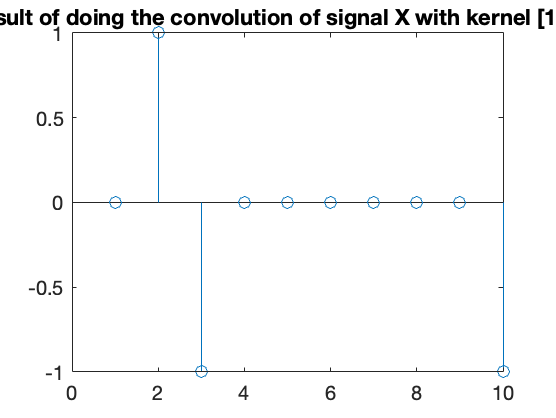

h5=[1 -2 1];
[~,z] = convN(y,h5,"zero");
figure
stem(z)
title("Result of doing the convolution of signal X with kernel [1 -2 1]")

The equivalence will be  [1 -2 1]

## 9. 2D CONV

#### Question 1: Program the 2D convolution with a 2D impulse response h. Do not forget to flip h. Reducethe size of the result to compute this convolution product.

clear; clc;
%Getting random integer numbers from -10 to 10 for 5*5 input matrix
I = randi([-10,10],5,5);
%Getting random integer numbers from 1 to 3 for 3*3 input matrix
k = randi([1,3],3,3);
%Final Result with the function created
Result = convolve(I, k)

Result =     46    76    66    37    17
    20    50    66    35   -21
     9    29    54    28     1
    -4    34    79    40   -13
    -3    13    35    20    -4


%Comparing the result with MATLAB conv2 Command
Result2 = conv2(I,k,'same')

Result2 =     46    76    66    37    17
    20    50    66    35   -21
     9    29    54    28     1
    -4    34    79    40   -13
    -3    13    35    20    -4


#### Question 2: Apply the elementary derivative along the two directions.

%For Elementary derivative we can apply a 3*3 Prewitt operator
%One for vertical direction and one for horizontal direction
hx = [ 1 0 -1;1 0 -1;1 0 -1];
hy = [ 1 1 1;0 0 0;-1 -1 -1];
%Convolving in vertical direction with 1st derivative
xResult = convolve(I, hx)

xResult =     14     2    -8   -11    -6
    13    16    -9   -26    -4
     3    12     7   -25   -10
     5    23     8   -33   -13
     6     9     9   -18   -15


%Convolving in horizontal direction with 1st derivative
yResult = convolve(I, hy)

yResult =     16    21    19    11     6
   -12    -8    -5    -3    -7
   -21   -26   -17   -10    -5
    14    11    19     7    10
     5     5    -2    -1    -1


#### Question 3: Define the second derivative on each direction and define the laplacien operator (2D sum).

%Applying second derivative
%One for vertical direction and one for horizontal direction
hxx = [ 0 -1 0;0 2 0;0 -1 0];
hyy = [ 0 0 0;-1 2 -1;0 0 0];
%Convolving in vertical direction with 2nd derivative
xxResult = convolve(I, hxx)

xxResult =    -11     7     5    -9     1
    24     8    -4    17     4
   -17    -6    13   -16    -7
     2   -14   -15     2     6
     0    21    12    15   -12


%Convolving in horizontal direction with 2nd derivative
yyResult = convolve(I, hyy)

yyResult =     -9    10     4    -7     1
    11     0    -4    10    -9
    -9    -6    21    -7   -10
    -1    -4    -2    14   -13
   -11    13    -7    22   -26


%2D Sum of both to get the convolution results with both direction
finalResult = xxResult + yyResult

finalResult =    -20    17     9   -16     2
    35     8    -8    27    -5
   -26   -12    34   -23   -17
     1   -18   -17    16    -7
   -11    34     5    37   -38


% Laplacian Operator
laplacian = [0 -1 0;-1 4 -1;0 -1 0];
%Applying Laplacian for convolution
laplacianResult = convolve(I, laplacian)

laplacianResult =    -20    17     9   -16     2
    35     8    -8    27    -5
   -26   -12    34   -23   -17
     1   -18   -17    16    -7
   -11    34     5    37   -38


# **Sampling**

## **10. NOISE**

#### **Question 1: **Create a gaussian white noise signal sn of length N = 10^6 (randn) or N = 2^20. Plot this signal.

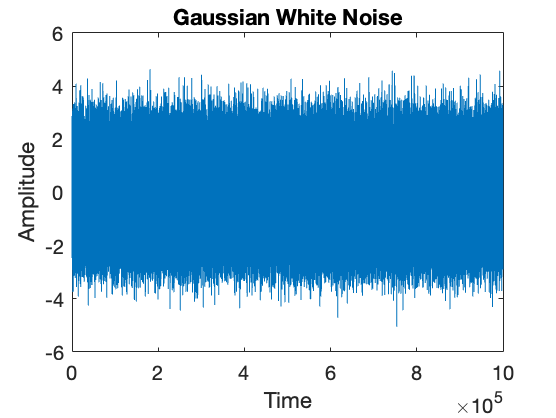

N = 1000000;
sigma = 5;
xmean = 0;
BINS = 50;
gaussian_signal = sqrt(sigma) * randn(1,length(N)) + xmean;

sn = randn(1,N);
sn = sn - mean(sn);

figure;
plot (1:N , sn)
title('Gaussian White Noise')
xlabel('Time'); ylabel('Amplitude');

#### **Question 2: **Estimate the pdf (probability density function) by computing the histogram of the outcomes (with 50 beans for example, normalize by the length of the signal). Plot the result.

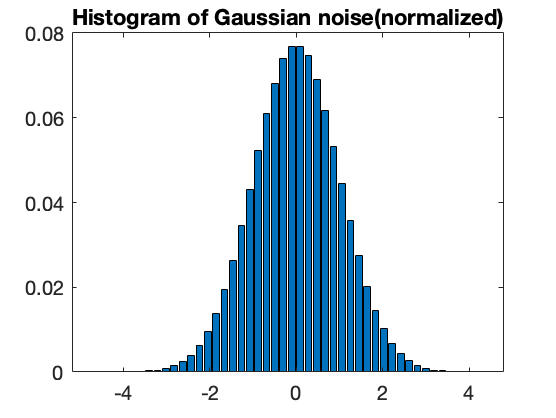

figure;
[HIST , center1] = hist(sn , BINS) ;
HIST = HIST./N;
bar (center1 , HIST)
title('Histogram of Gaussian noise(normalized)');

#### **Question 3: Compute the discrete Fourier transform ˆsn (fft) of sn. What is the length of ˆsn ? Plot 1 |sˆn| with the correctly graduated frequency axis by assuming sn is a sampled signal at the frequency fs = 1000Hz. Write in the comment of your program the exact frequency range.**

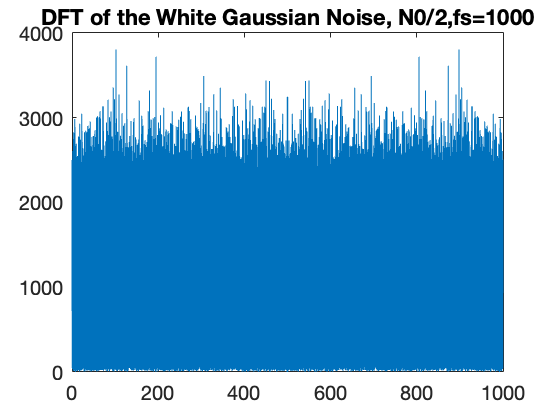

% ffshift : swap the position of the negative
% and positive frequencies of a spectrum 
% gotten with fft()
% fft -> fast fourier transform
dfty = fftshift( fft(sn) );

fs = 1000; % sampling frequency
T = 1/fs; % sampling interval
n = length(dfty); % length of the signal
sprintf("Length of the signal is %d",n);
bins = (0:T:(n-1)*T);
plot(bins, abs(dfty)), title("DFT of the White Gaussian Noise, N0/2,fs=1000");

#### **Question 4: Create the random signal sb by sub-sampling (1/2) sn. Respond to the same questions.**

#### **Conclusions ?**

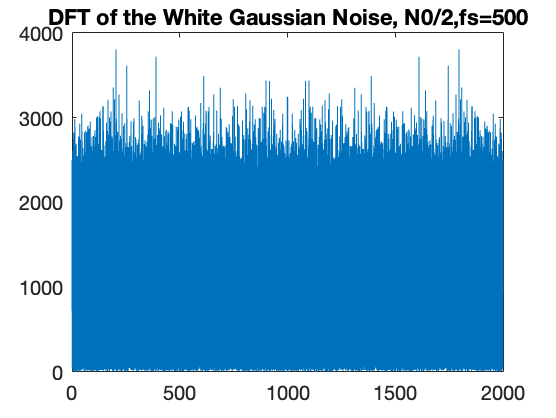

fs4 = 500; % sampling frequency
T4 = 1/fs4; % sampling interval
bins4 = (0:T4:(n-1)*T4);
plot(bins4, abs(dfty)), title("DFT of the White Gaussian Noise, N0/2,fs=500");

% the scale in x change comparing to the first signal sample (double)

The range of frequencies to span is also **doubled** to be from **0 to 2000**

we can notice that because it is WGN, its **both DFT is flat** and equal to N0/2

#### **Question 5: Create the random signal sc defined by : sc = sin(sn). Respond to the same questions.**

#### **Conclusions ?**

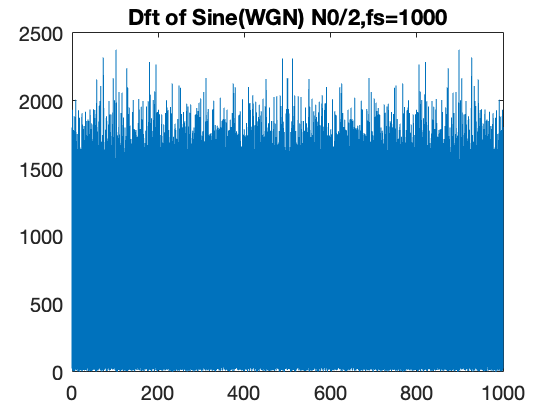

dfty5 = fftshift( fft( sin(sn) ));
bins5 = (0:T:((n-1)*T));
figure;
plot(bins5, abs(dfty5)), 
title("Dft of Sine(WGN) N0/2,fs=1000");

#### **Question 6: Create the random signal sf defined by : sf = K[1 1]/2 ∗ sn where K = max sn/ max sf .**

#### **Respond to the same questions. Conclusions ?**

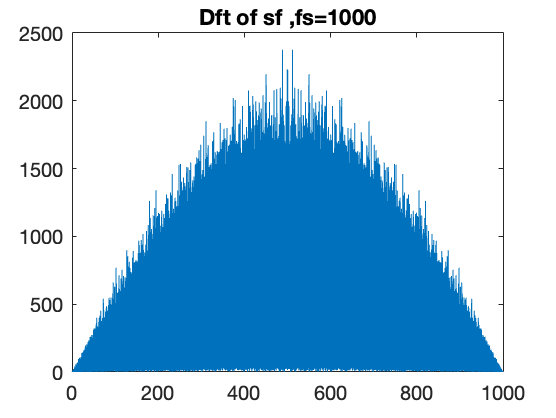

h=0.5*[1 1];

hf=fftshift(fft(h,n));
sf=hf.*dfty5;
sf=sf*max(dfty5)/max(sf);

figure;
plot(bins, abs(sf));
title("Dft of sf ,fs=1000");

#### **Question 7: Respond to the three first questions by considering the uniform white noise su (rand, remove the mean to have  ̄su = 0).**

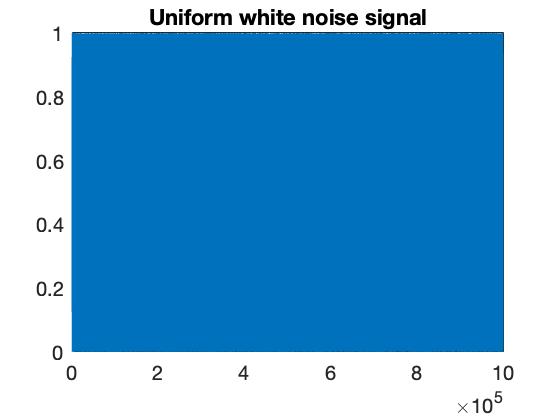

% first
x = [1:1:10^6];
y = rand(1,10^6);
plot(y), title("Uniform white noise signal");

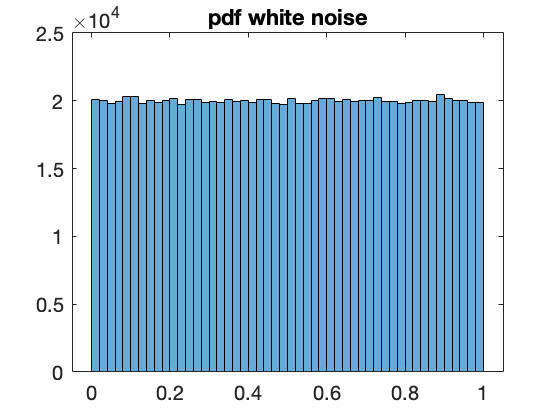


% second question
nbins = 50;
histogram(y,nbins), title("pdf white noise");

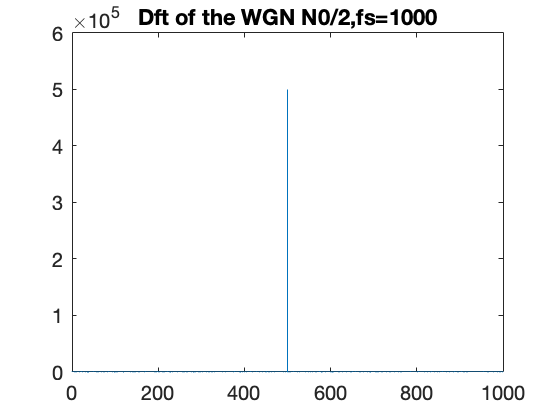


dfty = fftshift(fft(y));
fs = 1000; % sampling frequency
T = 1/fs; % sampling interval
n = length(dfty); % length of the signal
bins = (0:T:(n-1)*T);
plot(bins, abs(dfty)), title("Dft of the WGN N0/2,fs=1000");

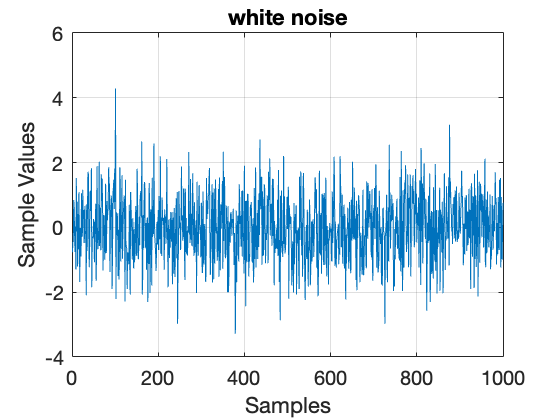


L=1000;
mean=0;
sigma= 1;
X=sigma*randn(L,1)+mean;
figure(1)
plot(X)
title('white noise');
xlabel('Samples')
ylabel('Sample Values')
grid on;

## 11. DETERMINISTIC SIGNALS

#### Question 1: Define a sinusoidal signal sd having a frequency fd = 1kHz, NT = 10 periods and N = 100 points. Plot sd.

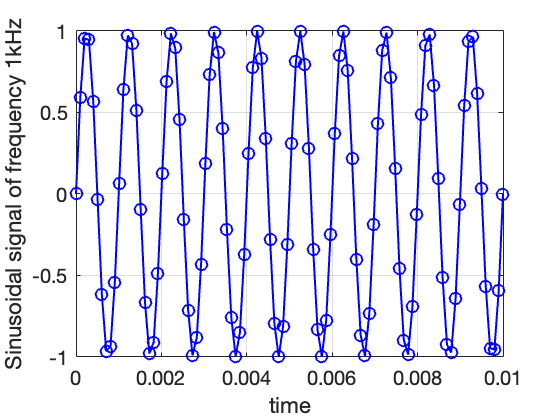

fd=1000; %frequency of 1kHz
NT=10; %number of periods
N=100; %number of points required

[t,sd] = plot_sine_wave(fd, NT, N);

#### Question 2: Compute the discrete Fourier transform ˆsd (fft) of sd. What is the length of ˆsd ? Plot |sˆd| with the correctly graduated frequency axis by deducing the sampling frequency fs.

#### Comment.

sd_ = fft(sd);
sd_abs = abs(sd_);
L=length(sd_);  
disp(["The length of fft(sd) is ", L]);

    "The length of fft(sd) is "    "100"



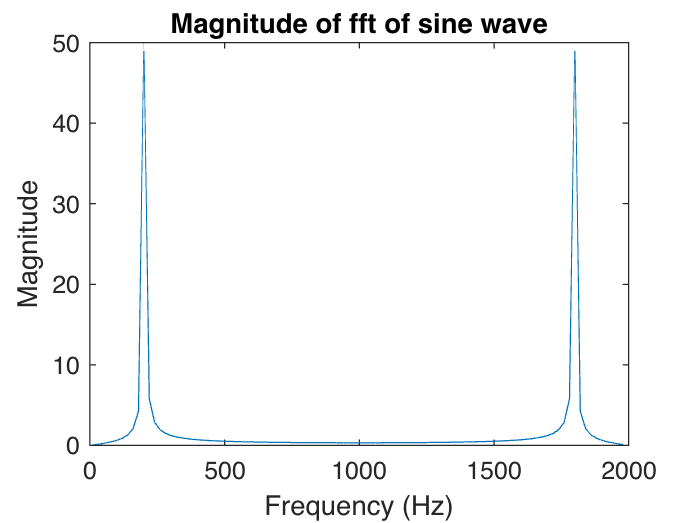

bins = [0: L-1];
fs=fd*2;
label_Hz = bins * fs/L;
plot(label_Hz, sd_abs);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude of fft of sine wave');

#### Question 3: Change fd, NT (can be non-integer) and N. Comment your observations.

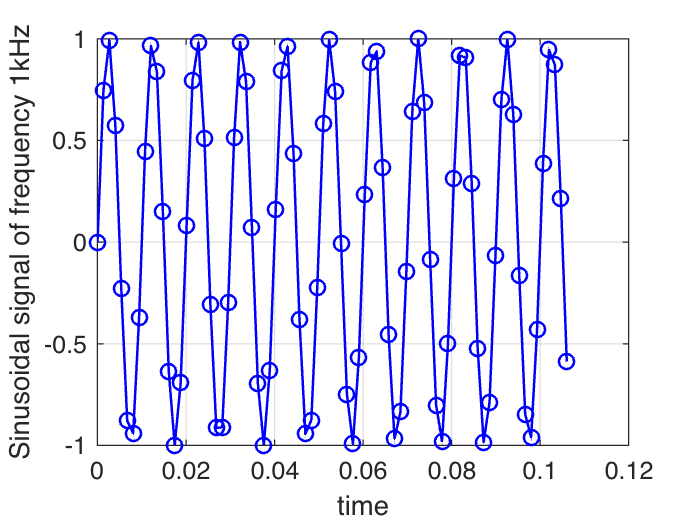

fd=100; %frequency of 1kHz
NT=10.6; %number of periods
N=80; %number of points required

plot_sine_wave(fd, NT, N);

#### Question 4: Define a square signal sq having a regular pattern period (between −1 and 1) for NT integer (do not use square). Plot sq.

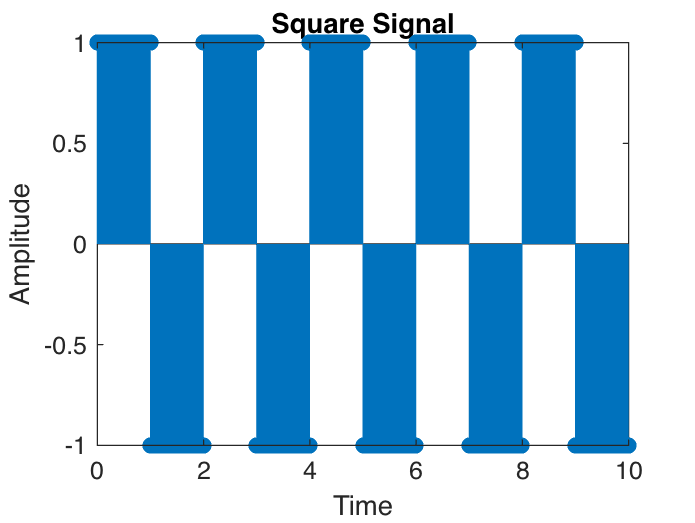

Nt = 10;
p = 1; 
ts = 0.01;
Sq = ones(1,Nt/ts);
for k=0:Nt/p
	j=((2*k+1)*(p/ts))+1;
	if(j~=Nt)
        Sq(j:j+(p/ts)-1) = -1;
    else
    	break
    end
                
end
Sq = Sq(1:Nt/ts);
x = 0:ts:Nt-ts; %Plot
stem(x,Sq);
title('Square Signal')
xlabel('Time')
ylabel('Amplitude')

#### Question 5: Compute the discrete Fourier transform ˆsd (fft) of sq. What is the length of ˆsq ? Plot |sˆq| with the correctly graduated frequency axis by deducing the sampling frequency fs.

#### Compare to the Fourier series of the continuous square signal. Conclusions ?

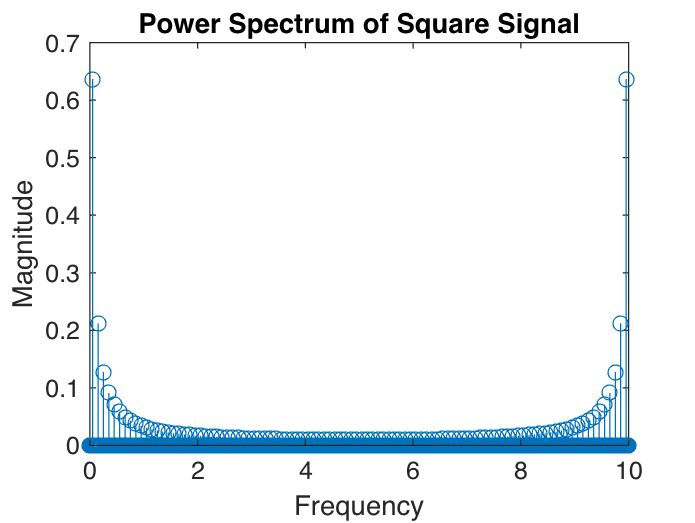

Sq_ = fft(Sq);
f = (0:length(Sq)-1)/ts;
figure(2)
stem(x,abs(Sq_/length(Sq_)))
title('Power Spectrum of Square Signal')
xlabel('Frequency')
ylabel('Magnitude')

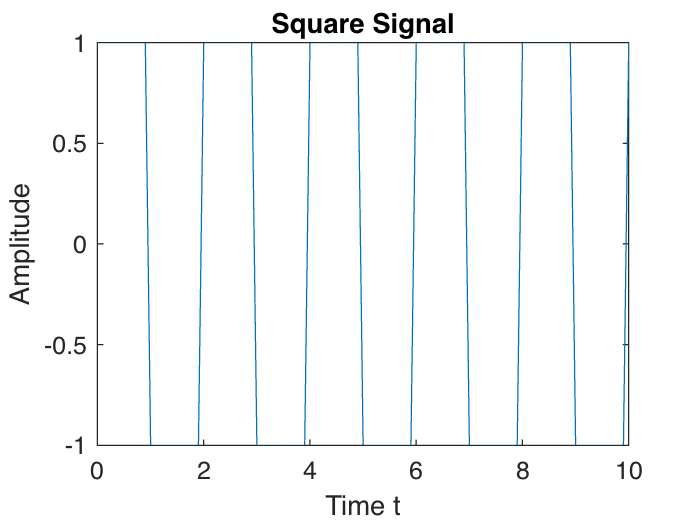


% Continuous :
Fs = 1/ts;
t = 0:ts:1;
f = Nt/(2*p);
x = square(2*pi*f*t);
X = fft(x);
MX = abs(X);
f = (0:length(X)-1)*Nt/length(X);
figure(3);
t = (0:ts:1)*Nt;
plot(t,x);
title('Square Signal')
xlabel('Time t')
ylabel('Amplitude')

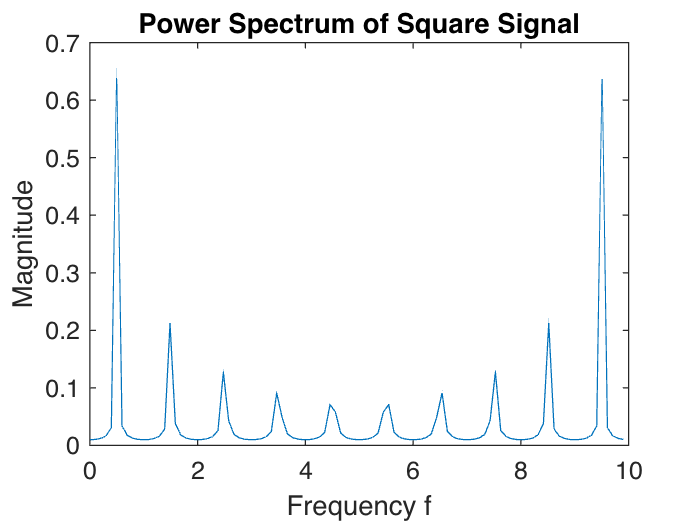

figure(4);
plot(f,MX/length(X));
title('Power Spectrum of Square Signal')
xlabel('Frequency f')
ylabel('Magnitude')

## 12. SOUND!

fSampRecord = 10000;
nBitsRecord = 16;
nChannelsRecord = 1;
deviceRecord = -1;
fSampPlay = 20000;
r = audiorecorder(fSampRecord, nBitsRecord, nChannelsRecord, deviceRecord);
record(r);
ch=sprintf(' <<< recording during 3s at frequency %6.0f Hz >>>', fSampRecord);
disp(ch)

 <<< recording during 3s at frequency  10000 Hz >>>


pause(3);
stop(r);
disp('-> playback !');

-> playback !


play(r); % sampling rate cannot be changed in the record
pause(4);
p = audioplayer(r); % create a player from the record
set(p, 'SampleRate', fSampPlay); % new sampling rate
ch=sprintf('-> playing at frequency %6.0f Hz', fSampPlay); disp(ch);

-> playing at frequency  20000 Hz


# DFT

## 13. 2D FREQUENCY PLAN

#### Question 1: Define an image as follows and display it

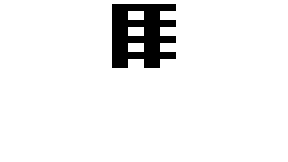

N=64;Ts=1/N; Fs=N; df=Fs/N;
Im(N/8:N/4,N/4+1:N/2) =1;
Im(1:N/4,N/2+1:N) = Im;
Im(N/4+1:N/2,:) = Im;
Im(N/2+1:3*N/4,:) = Im(1:N/4,:);
Im(3*N/4+1:N,:) = Im(1:N/4,:);
figure;
imshow(Im);

#### Question 2: Compute the If = DF T{Im} of the image and display real and imaginary parts (a + jb), modulus and phase (in degrees) [ρ, θ]. Do not forget to apply fftshift.

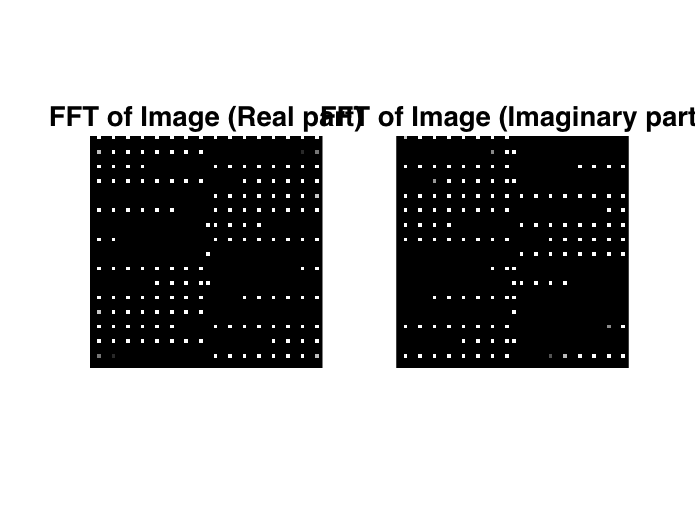

image_fft = fftshift(fft2(Im));
mag=abs(image_fft);                           
phase=(180/pi)*angle(image_fft);
figure;
subplot(1,2,1);
imshow(real(image_fft))
title("FFT of Image (Real part)")
subplot(1,2,2);
imshow(imag(image_fft))
title("FFT of Image (Imaginary part)")

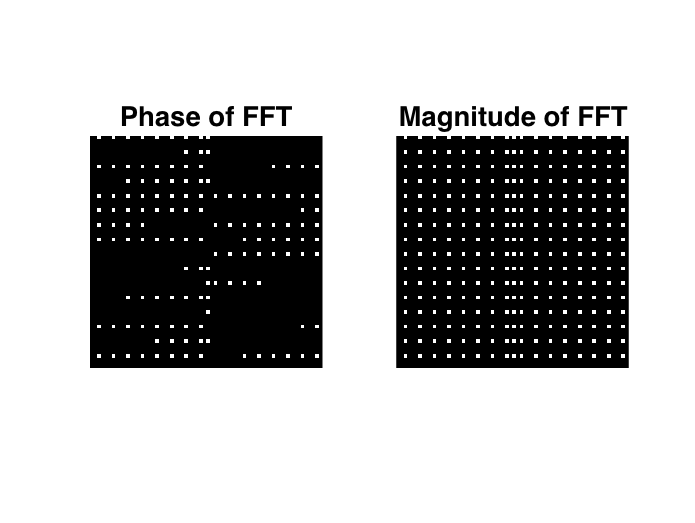


figure;
subplot(1,2,1);
imshow(phase)
title("Phase of FFT")
subplot(1,2,2);
imshow(mag)
title("Magnitude of FFT")

#### Question 3: Discuss about the frequency axes in the images. Interpret the different images (modulus and phase).

*After performing the fftshift() we shifted the DC component to the center of the image (position (0,0)). If R=C=N (square image) the point at column freq. u and row  freq. v  (u,v - coordinates in a FT image) represents a  sinusoid with freq. ω and  orientation θ. In the Fourier transform of an R=C digital image,  positions u and v indicate the number of repetitions  of the sinusoid in those directions. *

Phase spectrum tells us he displacement  the various sinusoids with the respect to their origin.

Magnitude spectrum tells us how much of each sinusoid component is present. Phase if much more important, because without it we basically do not know where to place our sinusoids. With only phase we can more or less get an idea of the image.

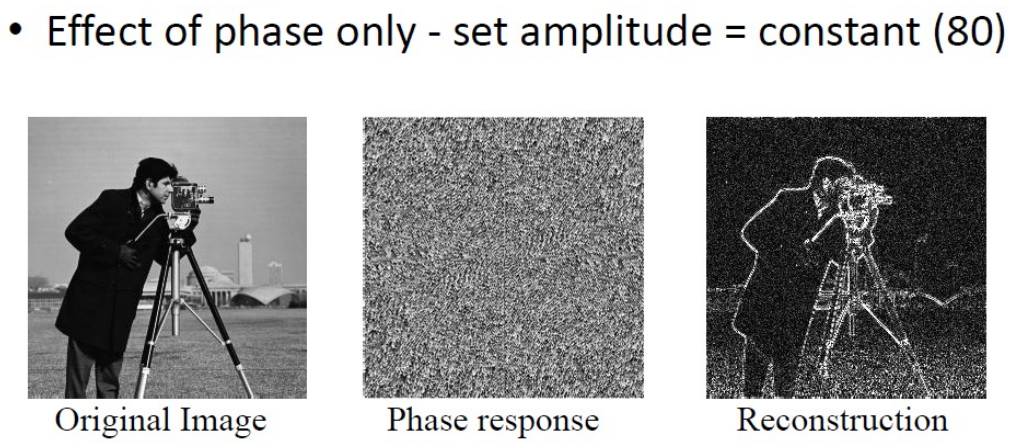

#### Question 4: Plot |If(u, 0)| and |If(0, v)| with the correct frequency range. Discuss about these results. What does If (u, v) represent.

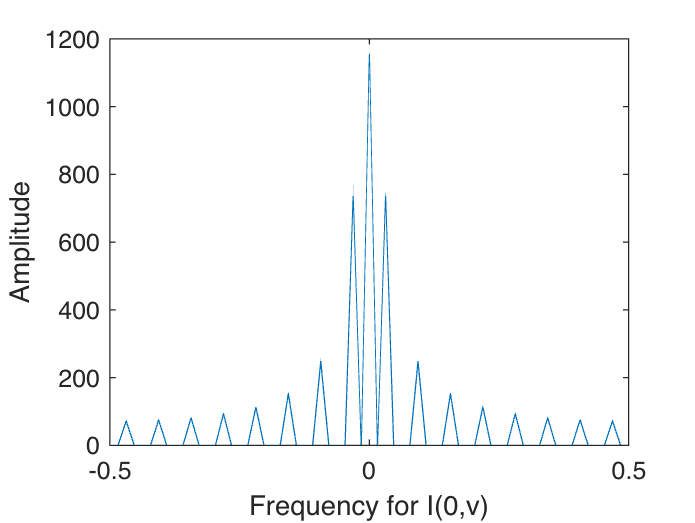

t = -32:1:31;
y = mag(33,:);
figure;
plot(t/64,y);
xlabel('Frequency for I(0,v)');
ylabel('Amplitude');

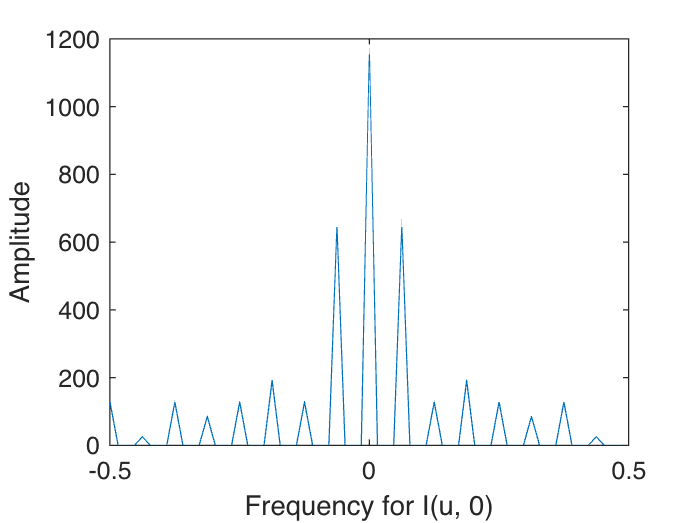

t = -32:1:31;
y = mag(:, 33);
plot(t/64,y);
xlabel('Frequency for I(u, 0)');
ylabel('Amplitude');

I(u,v) is the plane that we use to represent our DFT of the signal, each point I(u,v) on that  plane represents a sinusoidal grating of frequency *ω, *and orientation* θ. *In the Fourier transform of the image,  u and v indicate the number of repetitions of the sinusoid in those directions, where u represent the repetitions along the horizontal direction, and v represent the repetitions along the vertical direction

In our plot , We can see that for both directions there is  a peak at frequency=0 since I(0,0)  is the DC component and is the summation of all pixel values in the image. We also see thtat plot for I(u,0) has more peaks and oscilatioans since there are more lines in the horizontal direction in the image.

### 14. RECONSTRUCTION FORM MODULUS AND/OR PHASE

#### **Question 1: **Load a gray image Im1 and display this image.

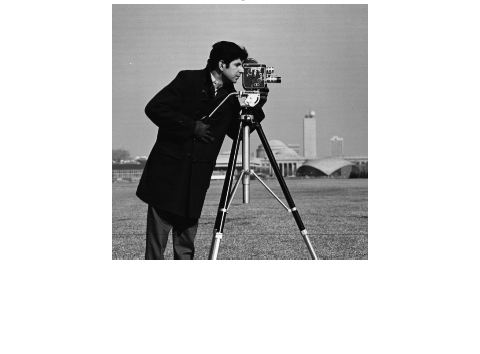

%Load the image
Im1=imread("cameraman.tif");
%Display the image
figure
imshow(Im1);title('Image 1');

#### **Question 2: **Compute and display the If1 = [ρ1, θ1] = DF T{Im1} with ρ1 = |If1| and θ1 = arg[If1] of this image Apply a log(ρ1 + 1) transformation to display the low amplitudes. Display the phase in degrees.

f1 = fftshift(fft2(Im1));
% Magnitude of the Fourier transform
mag=abs(f1);
% Phase of the Fourier transform
phase=exp(1i*angle(f1));
% Display the results
figure
subplot(2,2,1)
imshow(Im1);title('Original image');
subplot(2,2,2)
imshow(mag,[]);title('Fourier magnitude of Im1 (phi1)');
subplot(2,2,3)
imshow(phase,[]);title('Fourier phase of Im1 (tetha1)');

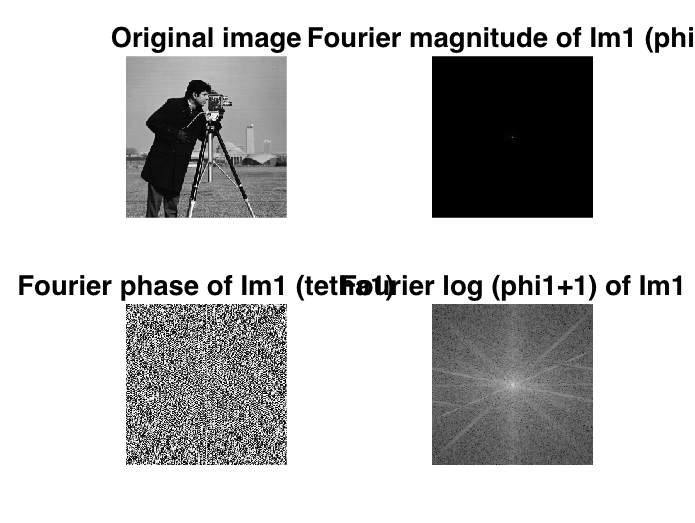

subplot(2,2,4)
imshow(log(mag+1),[]);title('Fourier log (phi1+1) of Im1');

#### **Question 3: **Thanks to the DT F^( −1), reconstruct an image from If (ρ1, 0) and another from If (1, θ1). Display the real parts of these reconstructions.

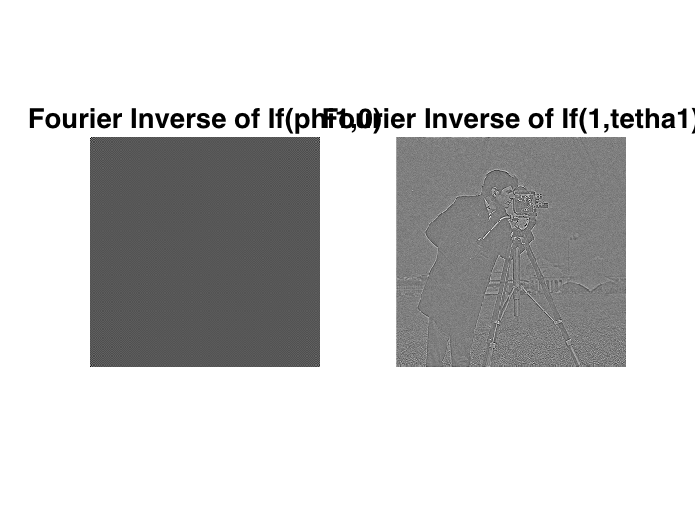

% Reconstruction of magnitude
Im1_mag = real(ifft2(fftshift(abs(fft2(Im1)))));
% Reconstruction of phase
Im1_phase = real(ifft2(fftshift(1*exp(i*angle(phase)))));
% Display the results
figure
subplot (1,2,1)
imshow(Im1_mag,[]);title('Fourier Inverse of If(phi1,0)');
subplot(1,2,2)
imshow(Im1_phase,[]);title('Fourier Inverse of If(1,tetha1)');

#### Question 4: Load a second gray image Im2 and display this image.

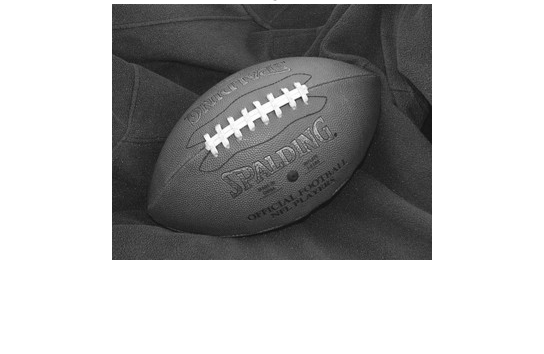

%Load the image
Im2=imread("football.jpg");
Im2 = rgb2gray(Im2);
%Display the image
figure;
imshow(Im2);title('Image 2');

#### Question 5: Compute and display the If2 = [ρ2, θ2] = DF T{Im2} with ρ2 = |If2| and θ2 = arg[If2] of this image.

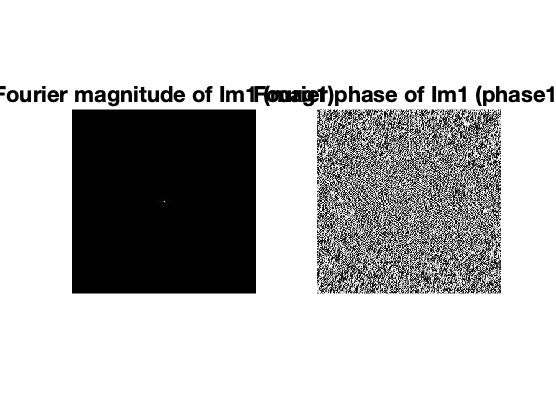

f2 = fftshift(fft2(Im1));

% Magnitude of the Fourier transform
mag2=abs(f2);
% Phase of the Fourier transform
phase2=exp(1i*angle(f2));
% Display the results
figure;
subplot(1,2,1)
imshow(mag2,[]);title('Fourier magnitude of Im1 (mag1)');
subplot(1,2,2)
imshow(phase2,[]);title('Fourier phase of Im1 (phase1)');

#### Question 6: Reconstruct an image from [ρ2, θ1] and another from [ρ1, θ2]. Display these reconstructions. Conclusion ?

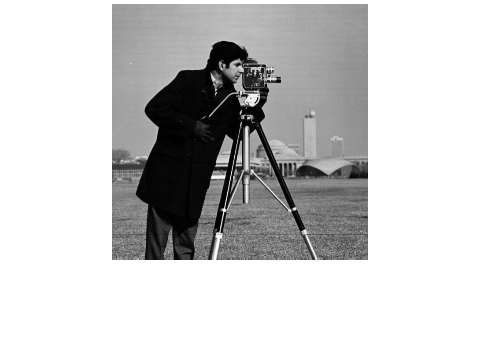

figure;
reconstructed1=abs(ifft2(fftshift(mag2.*exp(1i*angle(phase)))));
imshow(reconstructed1,[]);
title('Reconstructed from p2(pout) and theta(cameraman)');

Phase of the fourier transform represents the displacement  of the various sinusoids with the respect to their origin. Phase is more important, because without the location of sinusoids, we can not reconstruct the image properly. Thus, with phase only we can get an idea of the image in general.

# Recursive filtering

## 15. 1D filtering

#### Question 1: Construct a signal x[k]k∈[1,40] = δ(k − 20).

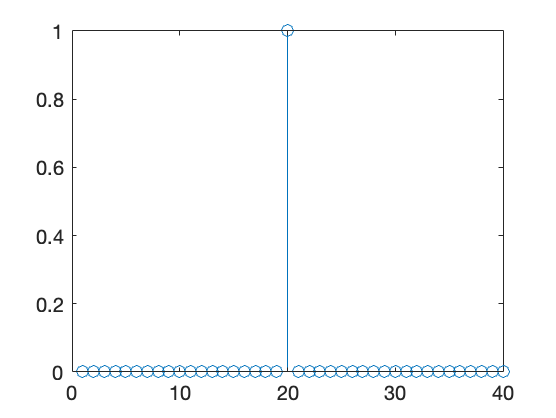

[~,xk] = DiracN(20,40); % The delta function
figure;
stem(xk);

#### Question 2: Apply the causal and the anti-causal parts of the smoothing filter on the signal. Analyze the result.

N = 7; 
AvF=ones(1,N); %A

Cfout = filter(AvF,1,xk);

ACf=filtfilt(1,1,xk); 
ACfout=filter(ACf,1,xk);


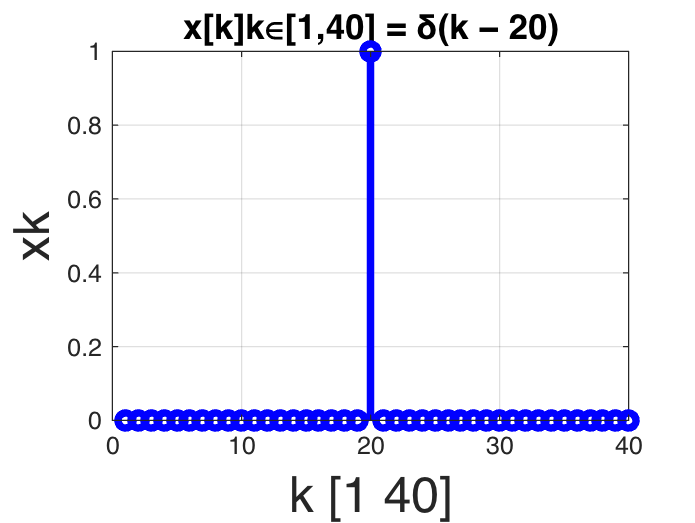


figure;
stem(xk,'linewidth',3,'color','b')
a= title('x[k]k∈[1,40] = δ(k − 20)');
set(a,'fontsize',14);
a= xlabel('k [1 40]');
set(a,'fontsize',20);
a = ylabel('xk');
set(a,'fontsize',20);

grid 

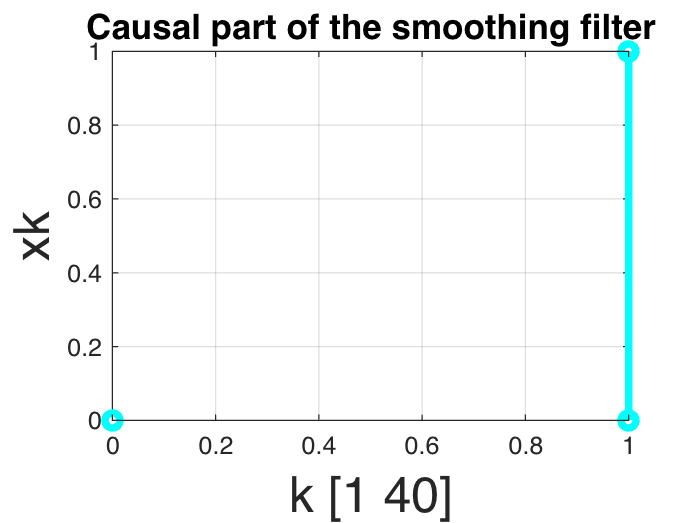


figure; 
stem(Cfout,xk,'linewidth',3,'color','c')
a= title('Causal part of the smoothing filter');
set(a,'fontsize',14);
a= xlabel('k [1 40]');
set(a,'fontsize',20);
a = ylabel('xk');
set(a,'fontsize',20);

grid

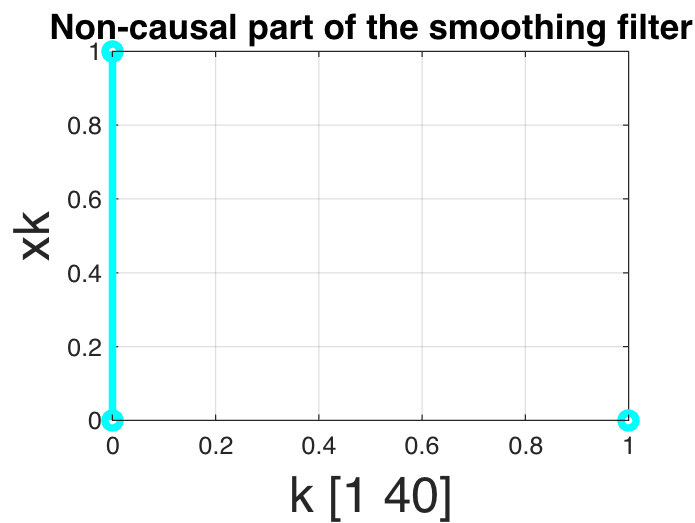


figure;
stem(ACfout,xk,'linewidth',3,'color','c')
a= title('Non-causal part of the smoothing filter');
set(a,'fontsize',14);
a= xlabel('k [1 40]');
set(a,'fontsize',20);
a = ylabel('xk');
set(a,'fontsize',20);

grid 

#### Question 3: Construct a signal x[k]k∈[1,40] = u[k − 10] − u[k − 30].

n0 = 10;
n1 =30;
k = 1:40;

[x1,y1] = Step(40,10);
[x2,y2] = Step(40,30);
xn = y1-y2;

#### Question 4: Apply the causal and the anti-causal parts of the derivative filter on the signal. Analyze the result.

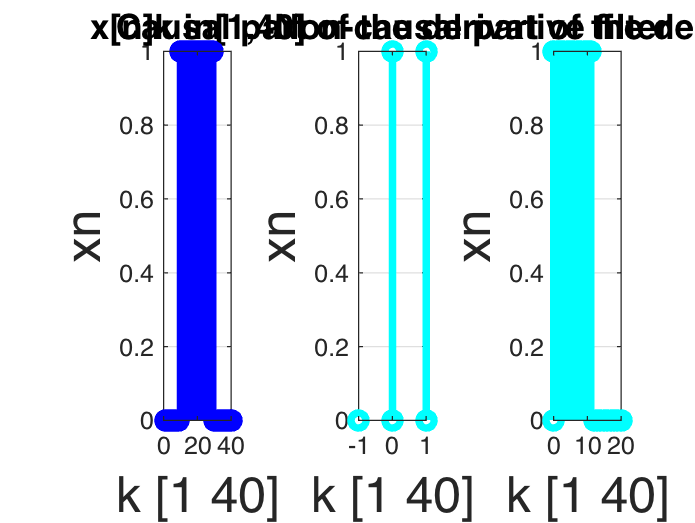

N = 5;
AvF=diff(xn); %A
Cfout = filter(AvF,1,xn);
ACf=filtfilt(1,1,xn); 
ACfout=filter(ACf,1,xn);
figure
subplot(1,3,1)
stem(k,xn,'linewidth',3,'color','b')
a= title('x[n]k in[1,40]');
set(a,'fontsize',14);
a= xlabel('k [1 40]');
set(a,'fontsize',20);
a = ylabel('xn');
set(a,'fontsize',20);
grid
subplot(1,3,2)
stem(Cfout,xn,'linewidth',3,'color','c')
a= title('Causal part of the derivative filter');
set(a,'fontsize',14);
a= xlabel('k [1 40]');
set(a,'fontsize',20);
a = ylabel('xn');
set(a,'fontsize',20);
grid

subplot(1,3,3)
stem(ACfout,xn,'linewidth',3,'color','c')
a= title('Non-causal part of the derivative filter');
set(a,'fontsize',14);
a= xlabel('k [1 40]');
set(a,'fontsize',20);
a = ylabel('xn');
set(a,'fontsize',20);
grid

## Exercise 1 – Canny-Deriche filtering

#### Question 1: Load a gray image Im and display this image.

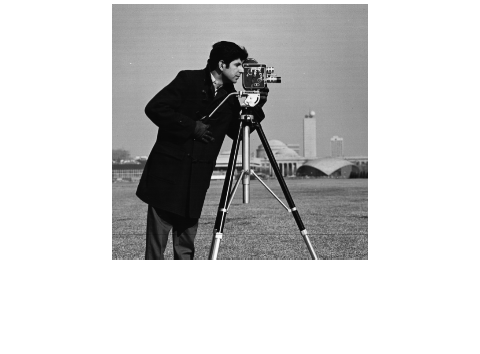

image = imread('cameraman.tif');
figure;
imshow(image)

#### Question 2: Apply the smoothing (derivative) filter along the columns (rows) of the images to obtain the component of the gradient on the horizontal direction.

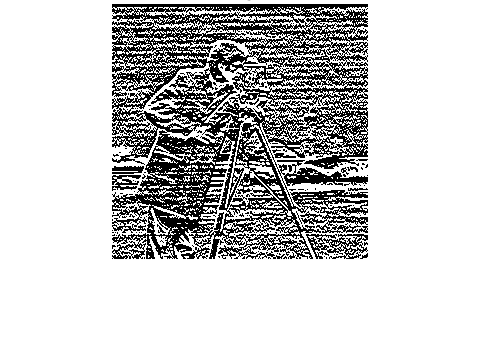

derivative_filter_col = [-1;0 ;1];
smooth_image = conv2(image, derivative_filter_col, 'same');
figure;
imshow(smooth_image)
title("Derivative along the columns")

#### Question 3: Apply the smoothing (derivative) filter along the rows (columns) of the images to obtain the component of the gradient on the vertical direction.

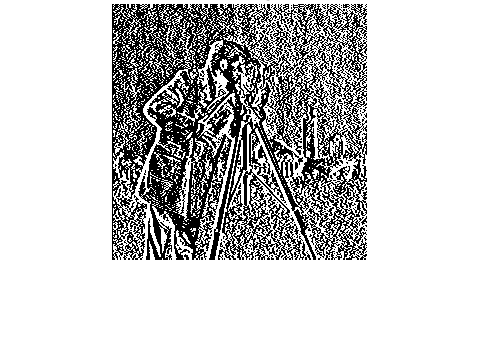

derivative_filter_row = [-1 0 1];
smooth_image2 = conv2(image, derivative_filter_row, 'same');
figure;
imshow(smooth_image2)
title("Derivative along the rows")

#### Question 4: Write an edge detection function (no maxima extraction). Display the modulus and the phase of the results.

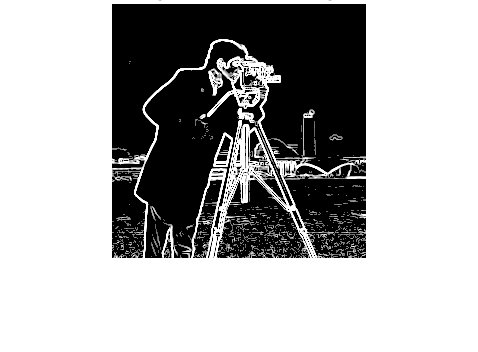

[sobel_image, phase] = edge_detection(image);
%Define a threshold value
Thresh=100;
sobel_image = max( sobel_image,Thresh);
sobel_image(sobel_image==round(Thresh))=0;

sobel_image=uint8(sobel_image);
figure,imshow(sobel_image);title('Edge detected Image');

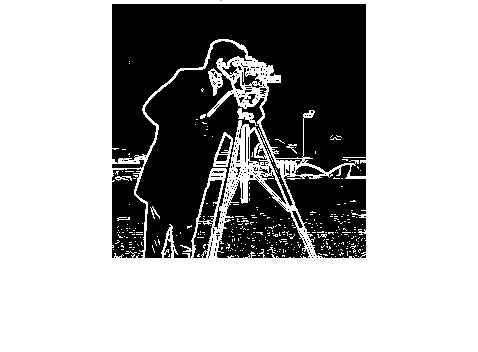


%% display the modulus

sobel_image = sobel_image./max(sobel_image) * 255;
figure;
imshow(sobel_image);
title("grad");

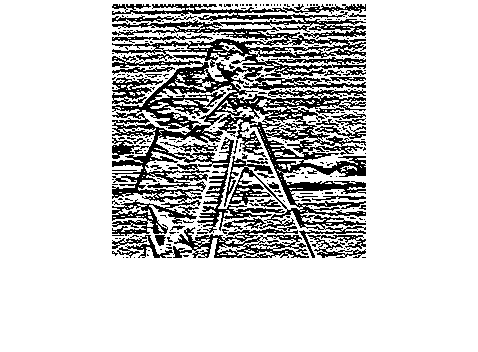

%% display the phase
figure;
imshow(phase);
title("phase");            

#### Question 5: Compare with convolution

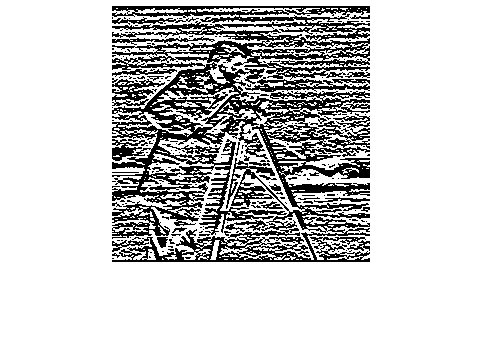

sobel_filter = [1 2 1; 0 0 0; -1 -2 -1];
Gx = conv2(image, sobel_filter);
figure;
imshow(Gx);

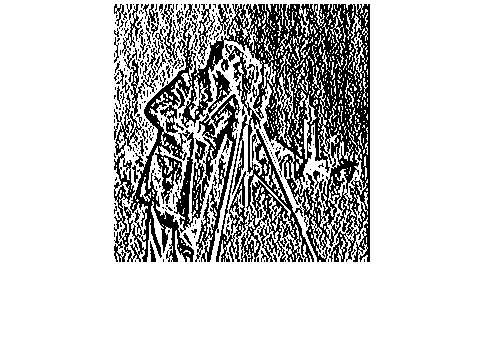



sobel_filter = transpose(sobel_filter);
Gy = conv2(image, sobel_filter);
figure;
imshow(Gy);

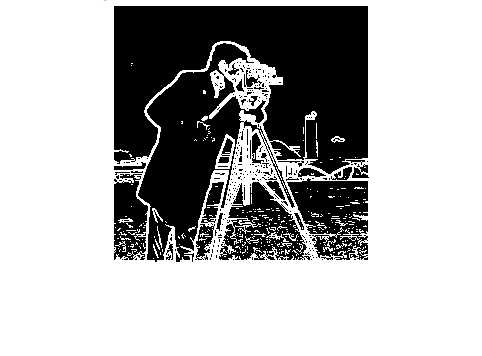


image_convoluted=hypot(Gx,Gy);

Thresh=100;
image_convoluted = max( image_convoluted,Thresh);
image_convoluted(image_convoluted==round(Thresh))=0;


figure;
imshow(image_convoluted)
title('edge detection with convolution')

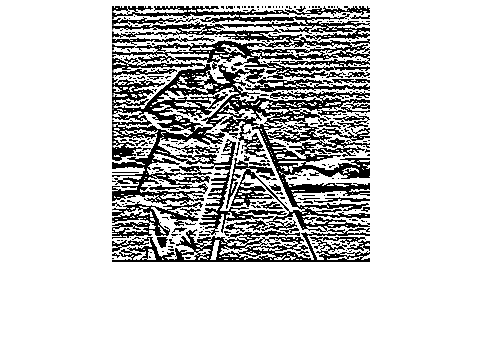

theta = 180* atan2(Gx, Gy)./3.14;
figure;
imshow(theta);
title('phase');

## APPENDIX (definition of functions)

Function code of the exercise Deterministic signals :

function [x,y]  = DiracN(n, N)
    if n<1 || n>N
        disp("Warning: n should be in range [1, N]");
        x = 0;
        y = 0;
        return
    else
        x = 1:N;
        y = zeros(1, N);
        y(n) = 1;      
    end
end


function [x,y] = Step(N,n)
    if (n<1) || (n>N)
        error("Warning: n should be in range [1,N]");
    else
        x = 1:N;
        y = zeros(1,N);
        y(n:N) = 1;
    end
end



function [x,y] = Ramp(N,n,a)

    if (n<1) || (n>N)
        error("Warning: n should be in range [1,N]");
    else
        x = 1:N;
        y = a * (x-n);
        y(1:(n-1)) = 0;
    end

   
end

function [x,y]  = GeomFunc(a, n, N)
    if (n<1) || (n>N)
        disp("Warning: n should be in range [1, N]");
        x = 0;
        y = 0;
        return
    else
    x = 1:N;
    y = zeros(1,N);
    for c = 1:N-n
        y(c+n) = a^c;
    end
    end
end

function [ x,y ] = boxf( N, n, a)
    %N is the length of the signal
    %n is the position (shift) of the BOX function
    %a is the half-width of the function
    if((n<(1+a)) || n > (N-a))
        disp('Warning: n is not in the range [1+a,N-a]')
    else
        x = 1:N;
        y = ones(size(x));
        y([1:(n-a-1),(n+a+1):end]) = 0;

    end

end

function [ x,y ] = sinusf( N, Fs, Fc)
    %N is the length of the signal, seconds
    %Fs sampling frequency, samples per second
    %Fc frequency of the sine function (hertz)
    dt = 1/Fs; %seconds per sample, period
    x = (0:dt:(N-dt));
    y = sin(2*pi*Fc*x);
end

Functions for causality:

%Causality function
function [x,z] = system1(x,y)
    z = zeros(1,length(x));
    for i = 1:length(x)-1
        z(i) = (y(i) + y(i+1))/2;
    end
end

Functions for stability:

function [x,z] = prim(x,y)
    sf = length(y);
    z = zeros(1, sf);
    for i = 1:sf
        z(i) = sum(y(1:i));
    end
end

function vect = shifted_step(n, N)
    if (n < 1) || (n > N)
        disp( ...
            "Warning: the displacement should be between 1 and "+ N + ...
            ". Returning the unshifted step.")
        vect = ones(1,N);
    else
        vect = zeros(1,N);
        vect(n:end) = 1;
    end
end

function vect = shifted_dirac(n, N)
    vect = zeros(1,N);
    if (n < 1) || (n > N)
        disp( ...
            "Warning: the displacement should be between 1 and "+ N + ...
            ". Returning the unshifted dirac")
        vect(1) = 1;
    else
        vect(n) = 1;
    end
end

function [x,z] = systemA(x,y)
    len = length(x);
    z = zeros(1,len);
    z(1) = x(1);
    for i = 2:len
        z(i) = y(i) + 2*z(i-1);
    end
end

function [x,z] = systemB(x,y)
    len = length(x);
    z = zeros(1,len);
    z(1) = x(1);
    for i = 2:len
        z(i) = y(i) + (1/3)*z(i-1);
    end
end

Function code of the exercise Convolution 1:

function convsignal=convolutionfunction(input, filter)
    N = length(input);
    M = length(filter);
    Ny = N + M -1;
    convsignal = zeros(1,Ny);
    for i = 1:N
          for k = 1:M
           convsignal(i+k-1) = convsignal(i+k-1) + filter(k)*input(i);
          end
    end

end

Function for invariance and linearity:

function y = y_response(x)
    N=length(x);
    for i=1:N-1
        if i>1
            y(i)=3*x(i-1) - 2*x(i) + x(i+1);
        end
    end
end

function y = shft(x,k)
    N=length(x);
    if k<0
        y=[zeros(1,abs(k)), x];
        y = y(1:N);
    elseif k>0
         y=x(1+k:end);
         y=[y zeros(1,(N-length(y)))];
    end
end

Function for 1D Conv:

function [t,y,zloc] = convN(x,h,pad)
zloc = find(h==0);
oloc1 = find(h~=0);
oloc2=find(h~=0);
%Output signal initialization
N = length(x);
M = length(h);
start = floor(length(h)/2)+1;
if nargin == 3
    switch pad
        case 'zero'
            y = zeros(1,N);
            %zero pad signals
            padx = zeros(1,(N+M-1)); 
            padx((M-1)/2+1:(end-(M-1)/2)) = x;
        case 'border' 
            y = zeros(1,N);
            padx = zeros(1,(N+M-1));
            %pads the signal with the border elements
            padx((M-1)/2+1:(end-(M-1)/2)) = x;
            %get logical array of the first
            % non signal element (edges at the beg)
            borderBeginIndex = padx(1:(M-1)/2+1) == 0;
            padx(borderBeginIndex) = x(1);
            %get logical array of the last
            % non signal element (edges at the end)
            borderEndIndex = padx((end-(M-1)/2)+1:end) == 0;
            padx(borderEndIndex) = x(end);
        case {'symmetry'} 
            y = zeros(1,N);
            padx = zeros(1,(N+M-1));
            %pads the signal with border ends
            borderSym = [x(1:((M-1)/2)) x((end-(M-1)/2+1):end)];
            padx((M-1)/2+1:(end-(M-1)/2)) = x;
            padx(1:(M-1)/2) = flip(borderSym(1:(M-1)/2));
            padx((end-(M-1)/2+1):end) = flip(borderSym((end-(M-1)/2+1):end));
        case {'periodic'} 
            %pads the signal periodically
            y = zeros(1,N);
            padx = zeros(1,(N+M-1));
            border = [x(1:((M-1)/2)) x((end-(M-1)/2+1):end)];
            padx((M-1)/2+1:(end-(M-1)/2)) = x;
            padx((end-(M-1)/2+1):end) = border(1:(M-1)/2);
            padx(1:(M-1)/2) = border((end-(M-1)/2+1):end);
        case {'borsym'}
            y = zeros(1,N);
            padx = zeros(1,(N+M-1));
            padx((M-1)/2+1:(end-(M-1)/2)) = x;
            borBeginSym = zeros(1,(M-1)/2);
            borEndSym = zeros(1,(M-1)/2);
            for i=1:((M-1)/2)
                borBeginSym(i) = x(1)*2-x(i+1);
                borEndSym(i) = x(end)*2-x(end-i);
            end
            padx(1:(M-1)/2) = flip(borBeginSym);
            padx((end-(M-1)/2+1):end) = borEndSym;            
        otherwise
            error('padding type not defined')
    end
    N = length(padx);
    x=padx;
else
    y = zeros(1,(N-2*(start-1)));
end
    for i = start:(N-start+1)
    subX = x((i-(M-1)/2):(i+(M-1)/2)); 
    sum = 0;
    %1D convolution with flipped kernel
    for j=1:M
        sum = sum+(h((length(h)+1)-j)*subX(j));
    end
        if rem(M,2)==0
          y(i-2) = sum;
        else 
          y(i-1) = sum;
        end
    end
    t=1:length(y);
end


Function for 2D Conv:

function B = convolve(A, k)
    [r, c] = size(A);
    [m, n] = size(k);
    %Flipping the kernel for convolution.
    %Rotating 180 degree counterclockwise.
    h = rot90(k, 2);
    %Extracting how many rows and columns to add for zero padding.
    center = floor((size(h)+1)/2);
    left = center(2) - 1;
    right = n - center(2);
    top = center(1) - 1;
    bottom = m - center(1);
    Rep = zeros(r + top + bottom, c + left + right);
    %Zero Padding
    for x = 1 + top : r + top
        for y = 1 + left : c + left
            Rep(x,y) = A(x - top, y - left);
        end
    end
        %Convolution:
        %Element wise multiplication and storing the sum in the center
        B = zeros(r , c);
    for x = 1 : r
        for y = 1 : c
            for i = 1 : m
                for j = 1 : n
                    q = x - 1;
                    w = y -1;
                    B(x, y) = B(x, y) + (Rep(i + q, j + w) * h(i, j));
                end
            end
        end
    end
end

For deterministic signals:

function [t, sd] = plot_sine_wave(fd,NT, N)
    p=1/fd; %length of one period in terms of time
    tp=p*NT; %length of ten periods in terms of time
    t=linspace(0,tp,N); %total length of time of ten periods divided into 100 points
    sd=sin(2*pi*fd*t); %sinosoidal signal for the time period t
    
    figure
    plot(t,sd,'bo-','LineWidth',1)
    grid on;
    xlabel("time");
    ylabel("Sinusoidal signal of frequency 1kHz");

end


For Canny Deriche filtering

function [B, theta]  = edge_detection(C)
    C = double(C);
    for i=1:size(C,1)-2
        for j=1:size(C,2)-2
            %Sobel mask for x-direction:
            Gx=((2*C(i+2,j+1)+C(i+2,j)+C(i+2,j+2))-(2*C(i,j+1)+C(i,j)+C(i,j+2)));
            %Sobel mask for y-direction:
            Gy=((2*C(i+1,j+2)+C(i,j+2)+C(i+2,j+2))-(2*C(i+1,j)+C(i,j)+C(i+2,j)));

            %The gradient of the image
            B(i,j)=sqrt(Gx.^2+Gy.^2);
            theta(i,j) = 180* atan2(Gx, Gy)./3.14;
           
            
        end
    end

end
